# **Integrate and Classify Normal Distributions **· Getting started

Tools to integrate normal (Gaussian) distributions in any dimensions with any parameters within any domain, compute pdf/cdf/inverse cdf of any function of a normal vector, and compute quantities concerning classification performance among two or more multinormals, such as error matrix and discriminability $d'$.

For function help, type:

doc integrate_normal
doc classify_normals
doc classify_normals_multi
doc norm_fun_cdf
doc norm_fun_pdf
doc norm_fun_inv

For a fuller description of the methods in this toolbox, see the accompanying paper [A method to integrate and classify normal distributions](https://arxiv.org/abs/2012.14331). Some of the examples marked here are described in the paper. If you use this toolbox, I would greatly appreciate it if you cite the paper, thanks.  

Bugs/questions/comments to abhranil.das@utexas.edu.

Abhranil Das, Center for Perceptual Systems, University of Texas at Austin

## Integrate normal in 1d

Define normal parameters, and a quadratic function of it, $-x^2+x+1$, i.e. `q(x)= -1*x^2 + 1*x + 1`:

mu=-2; v=3;

quad.q2=-1;
quad.q1=1;
quad.q0=1;

### Integrate the normal probability in the quadratic domain defined by $q(x)>0$:

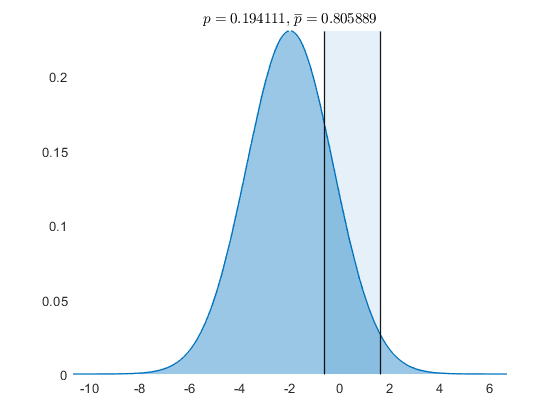

p = 0.1941

p=integrate_normal(mu,v,quad)

Most plots can be zoomed and panned.

### pdf/cdf/inverse cdf of $q(x)$

p=norm_fun_cdf([0 1 2],mu,v,quad)

p =     0.8059    0.9175    1.0000


f=norm_fun_pdf([0 1 2],mu,v,quad)

f =     0.0865    0.1696         0


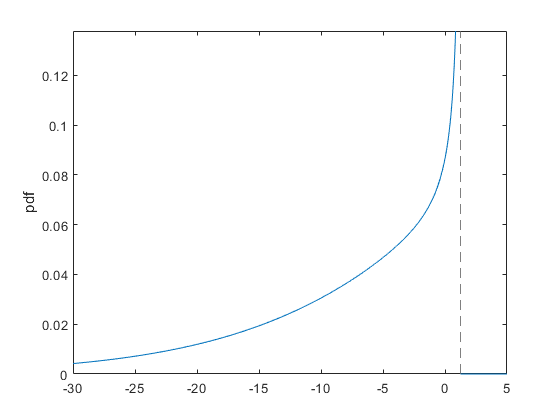

fplot(@(x) norm_fun_pdf(x,mu,v,quad),[-30 5]); ylabel 'pdf'

% 1st, 2nd and 3rd quartiles
x=norm_fun_inv([0.25 0.5 0.75],mu,v,quad)

x =   -12.2134   -5.0417   -0.7030


### normal probability in the domain defined by a non-quadratic function $f(x) =\cos x^2>0$

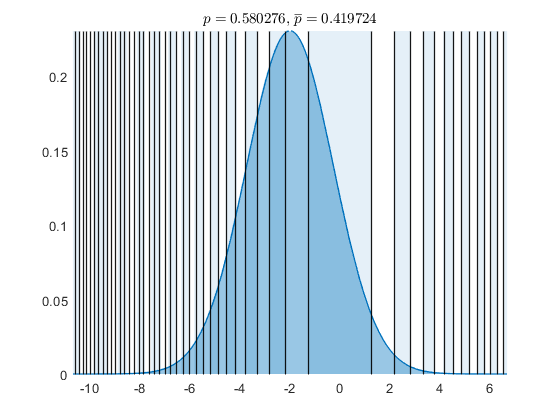

p = 0.5803

pc = 0.4197

bd_pts =   -10.5606  -10.4108  -10.2588  -10.1045   -9.9479   -9.7887   -9.6269   -9.4623   -9.2948   -9.1243   -8.9505   -8.7732   -8.5923   -8.4075   -8.2185   -8.0251   -7.8269   -7.6236   -7.4147   -7.1997   -6.9782   -6.7493   -6.5124   -6.2666   -6.0107   -5.7434   -5.4631   -5.1675   -4.8541   -4.5189   -4.1568   -3.7599   -3.3160   -2.8025   -2.1708   -1.2533    1.2533    2.1708    2.8025    3.3160    3.7599    4.1568    4.5189    4.8541    5.1675    5.4631    5.7434    6.0107    6.2666    6.5124


fun=@(x) cos(x.^2);
[p,pc,bd_pts]=integrate_normal(mu,v,fun,'dom_type','fun','fun_span',5,'fun_resol',500)

### pdf of $f(x)$

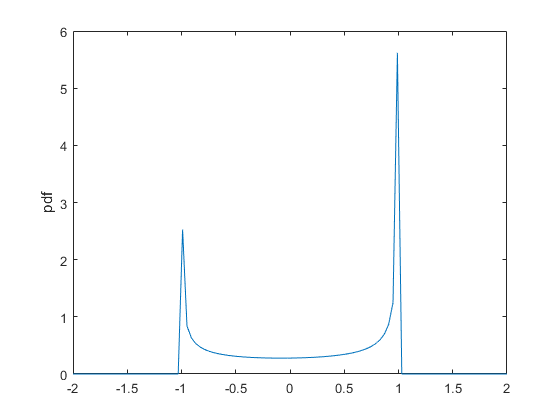

x=linspace(-2,2,100);
f=norm_fun_pdf(x,mu,v,fun,'fun_span',5,'fun_resol',500,'dx',1e-2);
plot(x,f); ylabel 'pdf'

### cdf of $f(x)$

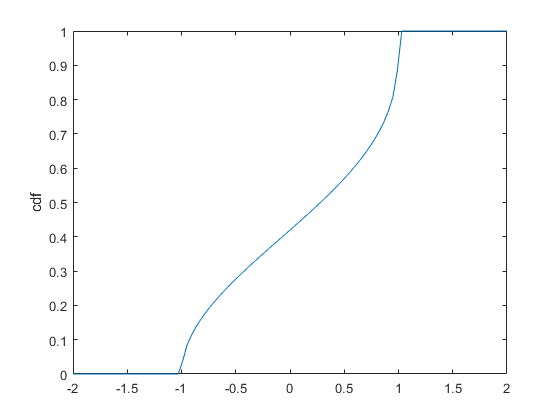

F=norm_fun_cdf(x,mu,v,fun,'fun_span',5,'fun_resol',500);
plot(x,F); ylabel 'cdf'

### Inverse cdf of $f(x)$

p=[0.5 0.75]; % median and 3rd quartile
x=norm_fun_inv(p,mu,v,fun)

x =     0.2803    0.8832


## Classify in 1d

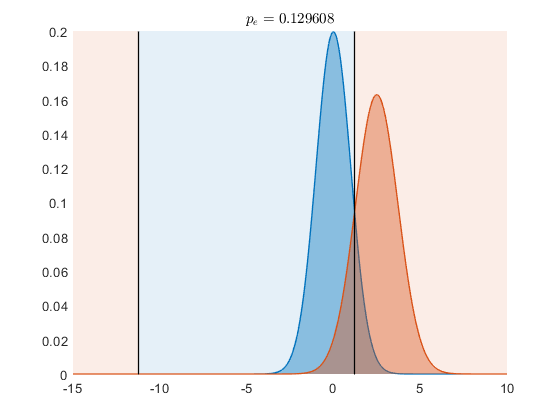

results = struct with fields:
          norm_bd: [1×1 struct]
      norm_bd_pts: [-11.2223 1.2223]
      norm_errmat: [2×2 double]
         norm_err: 0.1296
    norm_dprime_o: 2.2565
    norm_dprime_a: 2.2361
    norm_dprime_e: 2.2474


mu_1=0; v_1=1;
mu_2=2.5; v_2=1.5;

results=classify_normals([mu_1,v_1],[mu_2,v_2])

### with unequal priors and outcome values

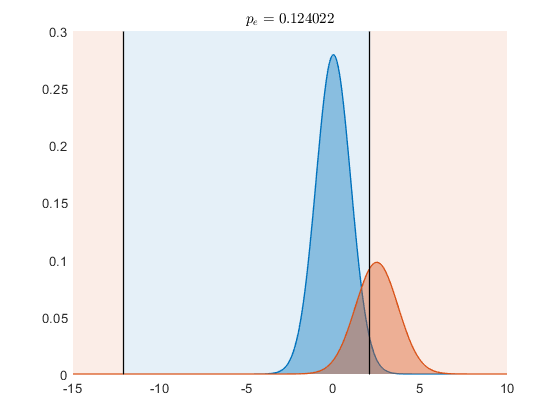

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_bd_pts: [-12.0987 2.0987]
    norm_errmat: [2×2 double]
       norm_err: 0.1240
    norm_valmat: [2×2 double]
       norm_val: 2.2509


results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[3 0; 0 1])

## Classify in 1d using samples

Priors are assumed prop. to sample sizes.

 
 Iteration   Func-count     min f(x)         Procedure
     0            1             -797         
     1            4             -799         initial simplex
     2            9             -799         shrink
     3           14             -799         shrink
     4           15             -799         reflect
     5           16             -799         reflect
     6           18             -799         contract inside
     7           23             -799         shrink
     8           28             -799         shrink
     9           33             -799         shrink
    10           38             -799         shrink
    11           43             -799         shrink
    12           48             -799         shrink
    13           53             -799         shrink
    14           58             -799         shrink
    15           63             -799         shrink
    16           68             -799         shrink
    17           73             -799         

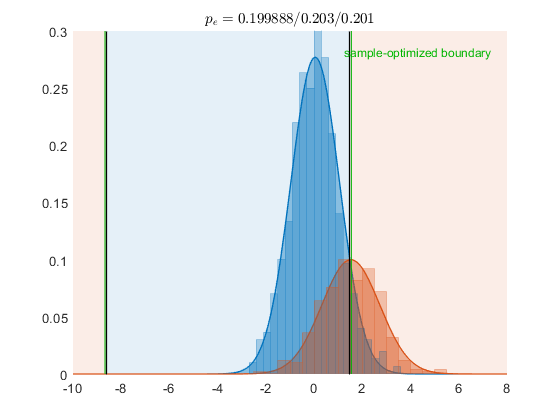

results = struct with fields:
            norm_bd: [1×1 struct]
        norm_bd_pts: [-8.6086 1.4845]
        norm_errmat: [2×2 double]
           norm_err: 0.1999
        samp_errmat: [2×2 double]
           samp_err: 0.2030
            samp_dv: {[700×1 double]  [300×1 double]}
        samp_opt_bd: [1×1 struct]
        samp_opt_dv: {[700×1 double]  [300×1 double]}
    samp_opt_bd_pts: [-8.6715 1.5474]
    samp_opt_errmat: [2×2 double]
       samp_opt_err: 0.2010


mu_1=0; v_1=1;
samp_1=normrnd(mu_1,sqrt(v_1),[700 1]);

mu_2=1.5; v_2=1.5;
samp_2=normrnd(mu_2,sqrt(v_2),[300 1]);

results=classify_normals(samp_1,samp_2,'input_type','samp')

## Integrate normal in 2d

### in a quadratic domain 

defined by $(x+y)^2 > x+1$, i.e.

`q(x,y)= [x y]*[1 1; 1 1]*[x;y] + [-1 0]*[x;y] -1 > 0`

mu=[-1; -1]; v=[1 0.5; 0.5 2];

quad.q2=[1 1; 1 1];
quad.q1=[-1;0];
quad.q0=-1;

% compare two integration algorithms
[p,pc,bd_pts]=integrate_normal(mu,v,quad) % ray method

p = 0.8214

pc = 0.1786

bd_pts = 	1.0e+03 *

   -0.0001    0.0021   -0.0001    0.0021   -0.0001    0.0021   -0.0001    0.0021   -0.0001    0.0021   -0.0001    0.0021   -0.0001    0.0020   -0.0001    0.0020   -0.0001    0.0019   -0.0002    0.0019   -0.0002    0.0019   -0.0002    0.0018   -0.0002    0.0018   -0.0002    0.0018   -0.0002    0.0017   -0.0002    0.0017   -0.0002    0.0017   -0.0002    0.0017   -0.0002    0.0017   -0.0002    0.0016   -0.0002    0.0015   -0.0002    0.0015   -0.0002    0.0014   -0.0002    0.0013   -0.0003    0.0013
   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0003   -0.0008   -0.0002   -0.0008   -0.0002   -0.0008   -0.0002   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0001   -0.0007   -0.0000   -0.0007    0.0000   -0.0007    0.0000   -0.0007    0.0001   -0.0006    0.0001   -0.0006    0.00

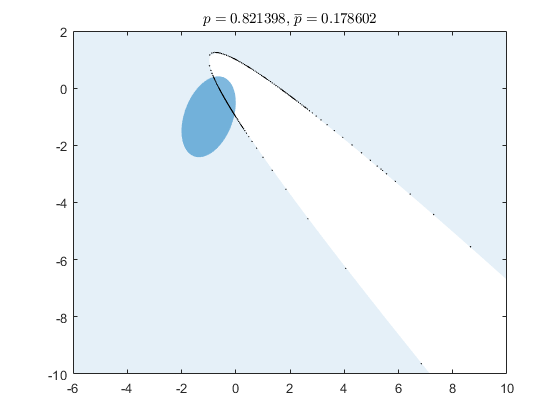

axis([-6 10 -10 2])

[p,pc]=integrate_normal(mu,v,quad,'method','gx2') % gx2 method

p = 0.8223

pc = 0.1777

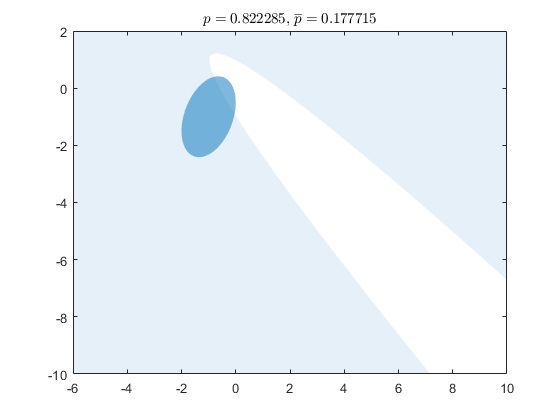

axis([-6 10 -10 2])

### [[paper fig. 2c]](https://arxiv.org/abs/2012.14331) In a non-quadratic domain

defined by $f(x,y) = x \sin y - y \cos x -1 > 0$:

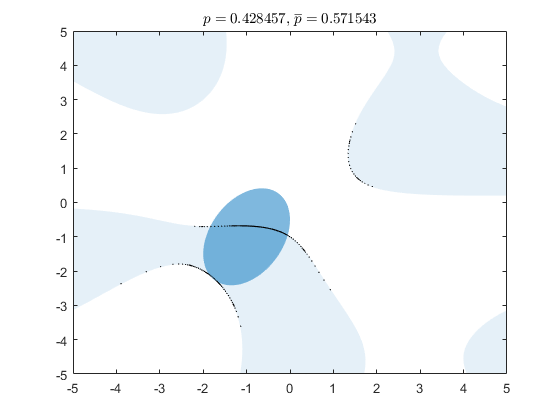

fun=@(x,y) x.*sin(y) - y.*cos(x) -1;
integrate_normal(mu,v,fun,'dom_type','fun','fun_span',3);
axis([-5 5 -5 5])

#### pdf of $f(x,y)$

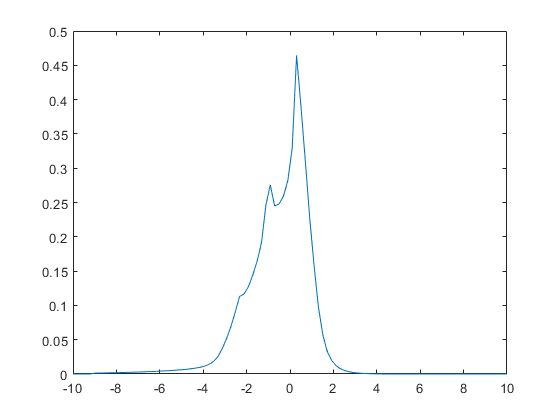

x=linspace(-10,10,100);
plot(x,norm_fun_pdf(x,mu,v,fun,'dx',1e-1))

## [[paper sec. 2.2.5]](https://arxiv.org/abs/2012.14331) probabilities of a function $x^y$ of a 2d normal

mu=[1;2]; v=.01*[1 1.6; 1.6 4];
fun=@(x,y) x.^y;

### cdf

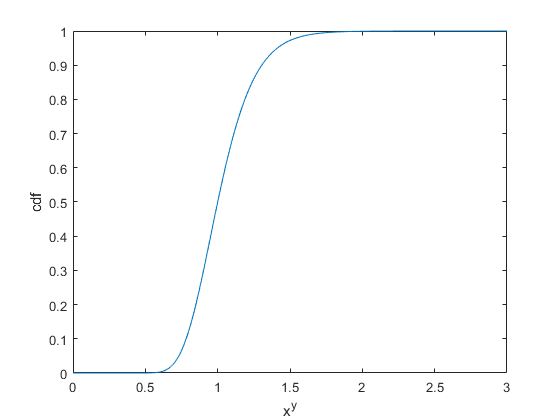

dx=.01; x=0:dx:3;
F=norm_fun_cdf(x,mu,v,fun,'fun_span',5,'fun_resol',500);
plot(x,F); xlabel x^y; ylabel 'cdf'

### pdf

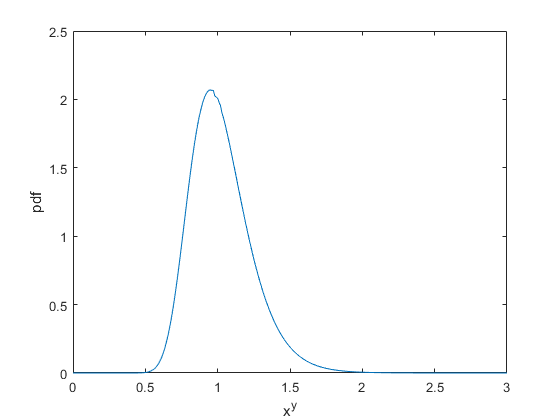

f=norm_fun_pdf(x,mu,v,fun,'fun_span',5,'fun_resol',500,'dx',1e-2);
plot(x,f); xlabel x^y; ylabel 'pdf'

Verify that pdf sums to 1:

sum(f)*dx

ans = 1.0000

### Mean of $x^y$

m=sum(x.*f)*dx

m = 1.0266

### sd of $x^y$

m2=sum(x.^2.*f)*dx;
sd=sqrt(m2-m^2)

sd = 0.2115

### median of $x^y$

norm_fun_inv(.5,mu,v,fun)

ans = 1.0000

## Joint probability of functions of a normal

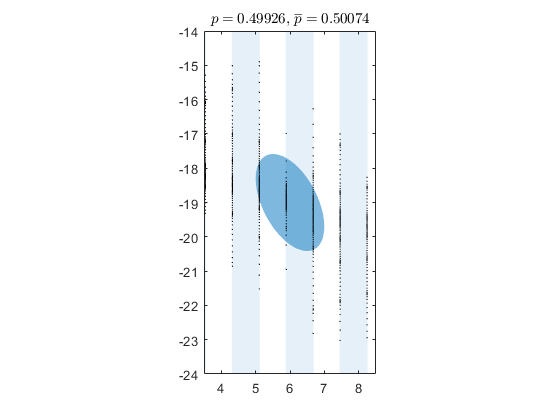

% (x,y) is a normal vector with these parameters:
mu=[6;-19];
v=[1 -.7; -.7 2];

% functions of the normal vector
fun1=@(x,y) cos(4*x);
fun2=@(x,y) cos(4*y);

% p(cos 4x > 0)
integrate_normal(mu,v,fun1,'dom_type','fun','fun_span',3); axis image

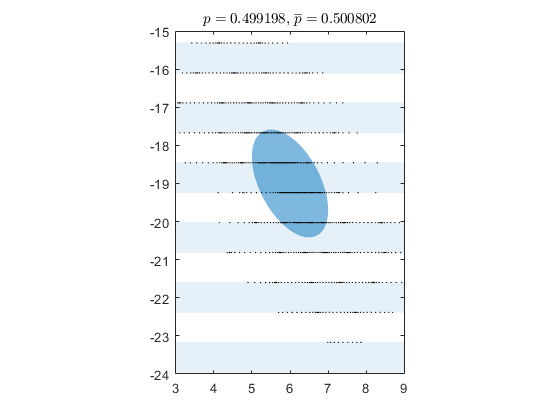

% p(cos 4y > 0)
integrate_normal(mu,v,fun2,'dom_type','fun','fun_span',3); axis image

Probability that $cos(4x)$ and $cos(4y)$ are both > 0, i.e. integrate the normal in the domain $\min (\cos 4x, \cos 4y)>0$:

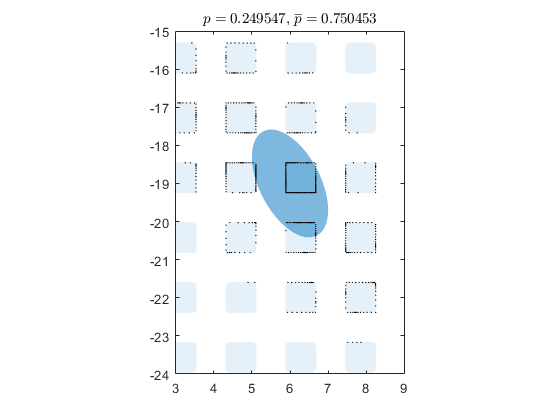

fun3=@(x,y) min(fun1(x,y),fun2(x,y));
p=integrate_normal(mu,v,fun3,'dom_type','fun','fun_span',3); axis image

Probability that $cos(4x) + cos(4y) > 0.5$, i.e. integrate the normal in the domain $cos(4x) + cos(4y) + 0.5 > 0$

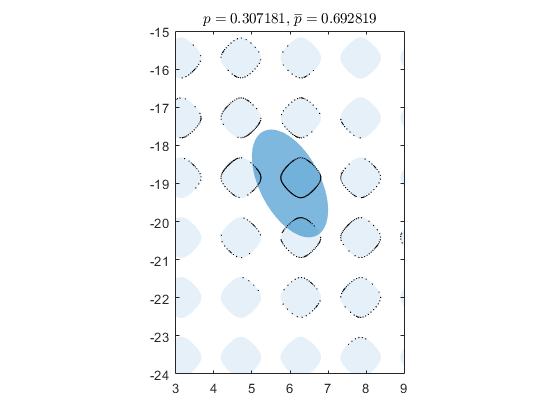

fun4=@(x,y) fun1(x,y)+fun2(x,y)-0.5;
p=integrate_normal(mu,v,fun4,'dom_type','fun','fun_span',3); axis image

Percentage points (inverse cdf):

p=[0.5 0.75];
x=norm_fun_inv(p,mu,v,fun4)

x =    -0.4999    0.2210


## Classify two 2d normals with the same mean

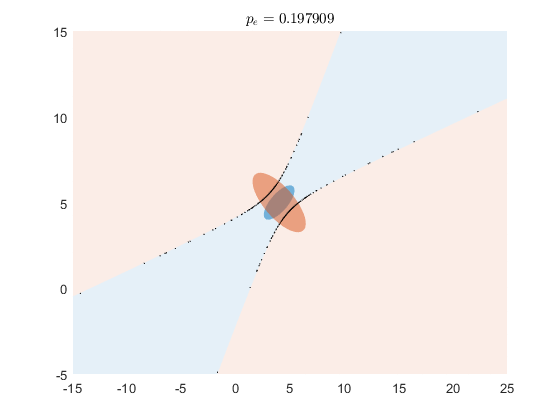

results_ray = struct with fields:
          norm_bd: [1×1 struct]
      norm_bd_pts: [2×414 double]
      norm_errmat: [2×2 double]
         norm_err: 0.1979
    norm_dprime_o: 1.6982
    norm_dprime_a: 0
    norm_dprime_e: 0


mu_1=[4; 5]; v_1=[2 1; 1 1];
mu_2=mu_1; v_2=3*[2 -1; -1 1];

% compare two integration algorithms
results_ray=classify_normals([mu_1,v_1],[mu_2,v_2]) % ray method

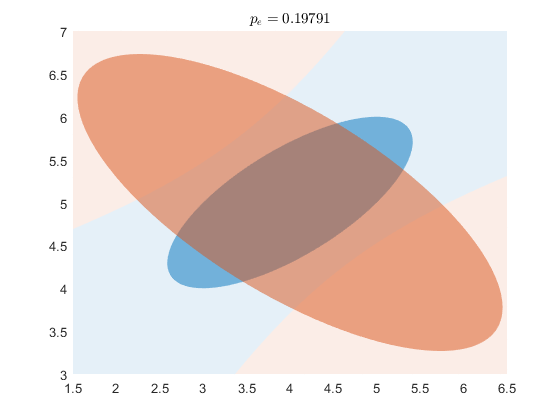

results_gx2 = struct with fields:
          norm_bd: [1×1 struct]
      norm_errmat: [2×2 double]
         norm_err: 0.1979
    norm_dprime_o: 1.6982
    norm_dprime_a: 0
    norm_dprime_e: 0


results_gx2=classify_normals([mu_1,v_1],[mu_2,v_2],'method','gx2') % gx2 method

## [[paper fig. 2d]](https://arxiv.org/abs/2012.14331) Classify in 2d with custom boundaries and from samples

mu_1=[2;4]; v_1=[1 1.5; 1.5 3];
mu_2=[5;0]; v_2=[3 0; 0 1];

Ray method:

results_ray=classify_normals([mu_1,v_1],[mu_2,v_2])

results_ray = struct with fields:
          norm_bd: [1×1 struct]
      norm_bd_pts: [2×512 double]
      norm_errmat: [2×2 double]
         norm_err: 0.0079
    norm_dprime_o: 4.8272
    norm_dprime_a: 4.4477
    norm_dprime_e: 5.1149


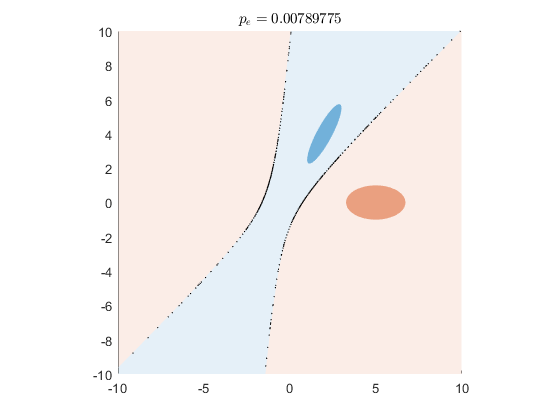

axis image; axis([-10 10 -10 10])

format long; results_ray.norm_err

ans =    0.007897753149045


Compare with generalized chi square method:

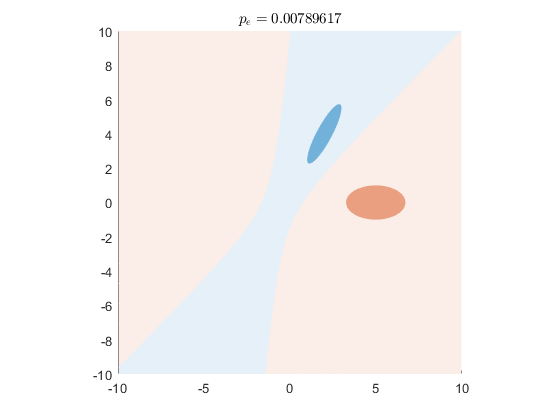

results_gx2=classify_normals([mu_1,v_1],[mu_2,v_2],'method','gx2'); 
axis image; axis([-10 10 -10 10])

format long; results_gx2.norm_err

ans =    0.007896171961222


Now pass the optimal domain in function format:

dom=results_gx2.norm_bd;

a_x2=dom.q2(1,1);
a_y2=dom.q2(2,2);
a_xy=dom.q2(1,2)+dom.q2(2,1);
a_x=dom.q1(1);
a_y=dom.q1(2);
a_0=dom.q0;

dom_fun=@(x,y) a_x2*(x.^2)+a_y2*(y.^2)+a_xy*(x.*y)+a_x*x+a_y*y+a_0;
results_fun=classify_normals([mu_1,v_1],[mu_2,v_2],'dom',dom_fun,'dom_type','fun')

results_fun = struct with fields:
    norm_bd_pts: [2×326 double]
    norm_errmat: [2×2 double]
       norm_err: 0.007897751962520


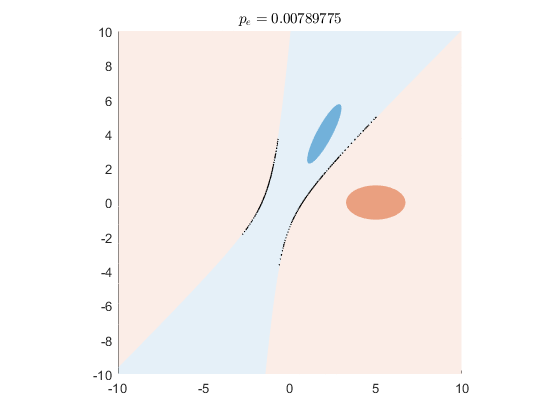

axis image; axis([-10 10 -10 10])

results_fun.norm_err

ans =    0.007897751962520


format

Now supply a custom linear boundary in quadratic coefficients format:

linear_bd.q2=zeros(2);
linear_bd.q1=[-.7;1];
linear_bd.q0=0;

results_linear=classify_normals([mu_1,v_1],[mu_2,v_2],'dom',linear_bd)

results_linear = struct with fields:
    norm_bd_pts: [2×300 double]
    norm_errmat: [2×2 double]
       norm_err: 0.0133


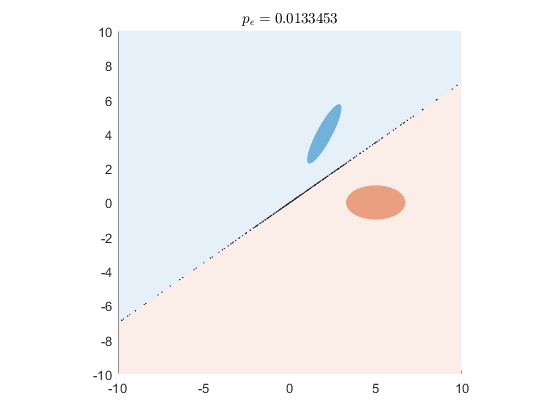

axis image; axis([-10 10 -10 10])

Now supply the linear boundary in function format:

linear_bd_fun=@(x,y) y-0.7*x;
results_linear_fun=classify_normals([mu_1,v_1],[mu_2,v_2],'dom',linear_bd_fun,'dom_type','fun')

results_linear_fun = struct with fields:
    norm_bd_pts: [2×195 double]
    norm_errmat: [2×2 double]
       norm_err: 0.0133


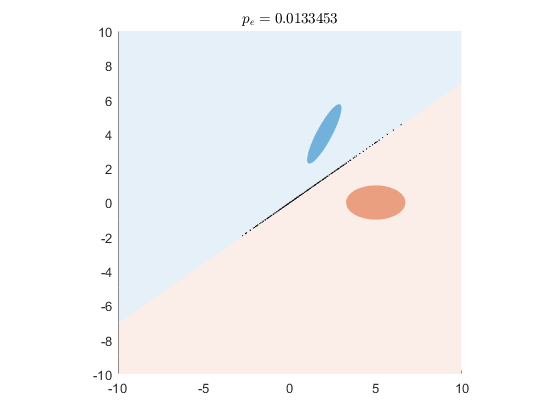

axis image; axis([-10 10 -10 10])

Now classify using samples:

n_samp=1e3;
samp_1=mvnrnd(mu_1,v_1,n_samp);
samp_2=mvnrnd(mu_2,v_2,n_samp);

results_samp=classify_normals(samp_1,samp_2,'input_type','samp')

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            -1984         
     1            7            -1984         initial simplex
     2            9            -1984         contract outside
     3           17            -1984         shrink
     4           25            -1984         shrink
     5           33            -1984         shrink
     6           41            -1984         shrink
     7           49            -1984         shrink
     8           57            -1984         shrink
     9           65            -1984         shrink
    10           73            -1984         shrink
    11           81            -1984         shrink
    12           89            -1984         shrink
    13           97            -1984         shrink
    14          105            -1984         shrink
    15          113            -1984         shrink
    16          121            -1984         shrink
    17          129            -1984         s

results_samp = struct with fields:
            norm_bd: [1×1 struct]
        norm_bd_pts: [2×524 double]
        norm_errmat: [2×2 double]
           norm_err: 0.0074
      norm_dprime_o: 4.8776
      norm_dprime_a: 4.5222
      norm_dprime_e: 5.2007
        samp_errmat: [2×2 double]
           samp_err: 0.0080
        samp_dprime: 4.8178
            samp_dv: {[1000×1 double]  [1000×1 double]}
        samp_opt_bd: [1×1 struct]
        samp_opt_dv: {[1000×1 double]  [1000×1 double]}
    samp_opt_bd_pts: [2×32820 double]
    samp_opt_errmat: [2×2 double]
       samp_opt_err: 0.0080
    samp_opt_dprime: 4.8178


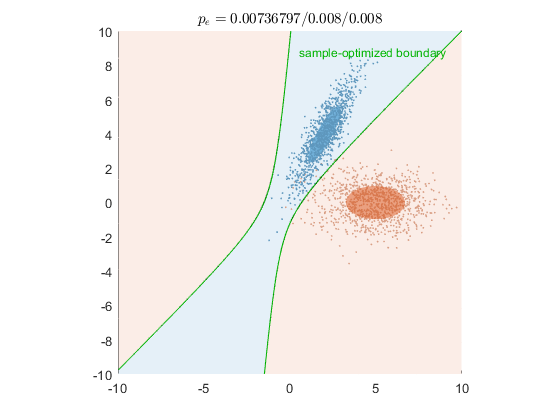

axis image; axis([-10 10 -10 10])

% modify the sample-optimized boundary and classify with it
custom_bd=results_samp.samp_opt_bd;
custom_bd.q2=custom_bd.q2+.1;
custom_bd.q1=custom_bd.q1-2.5;
custom_bd.q0=custom_bd.q0+5;

results_samp_custom=classify_normals(samp_1,samp_2,'input_type','samp','dom',custom_bd)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            -1956         
     1            7            -1964         initial simplex
     2            8            -1964         reflect
     3           10            -1972         expand
     4           11            -1972         reflect
     5           12            -1972         reflect
     6           14            -1976         expand
     7           16            -1978         reflect
     8           17            -1978         reflect
     9           18            -1978         reflect
    10           19            -1978         reflect
    11           20            -1978         reflect
    12           22            -1978         contract inside
    13           24            -1978         contract outside
    14           32            -1978         shrink
    15           34            -1978         contract inside
    16           36            -1978         contract inside
    17     

results_samp_custom = struct with fields:
        norm_bd_pts: [2×442 double]
        norm_errmat: [2×2 double]
           norm_err: 0.0209
        samp_errmat: [2×2 double]
           samp_err: 0.0220
            samp_dv: {[1000×1 double]  [1000×1 double]}
        samp_opt_bd: [1×1 struct]
        samp_opt_dv: {[1000×1 double]  [1000×1 double]}
    samp_opt_bd_pts: [2×27166 double]
    samp_opt_errmat: [2×2 double]
       samp_opt_err: 0.0110


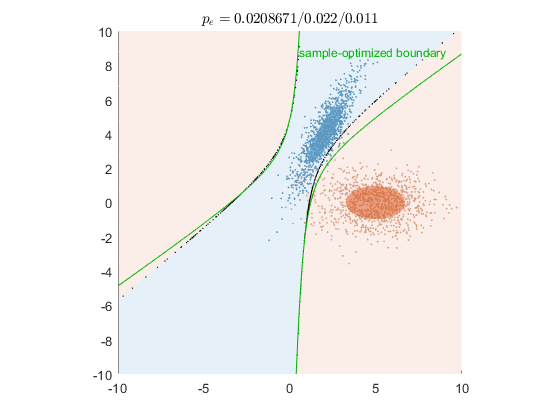

axis image; axis([-10 10 -10 10])

## Use integration/classification domains in three different formats

mu=[1;7];
v=[1 .5; .5 2];

Integrate this 2d normal in the domain defined by the line $y>1$, using three different domain formats.

### Ray-scan format

Construct the domain as a ray-scan function, which specifies the initial sign and crossing points of the domain along any ray.

open line_ray_scan

Plot the domain boundary:

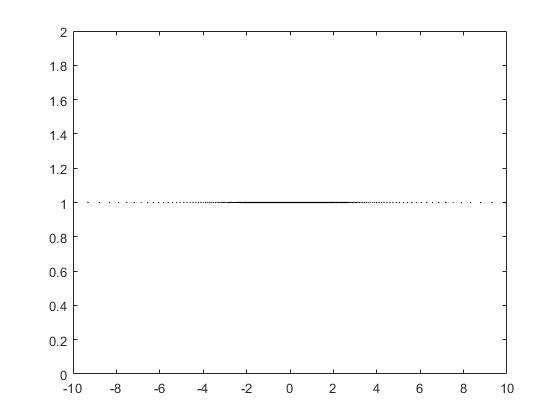

plot_boundary(@line_ray_scan,2,'dom_type','ray_scan')
axis([-10 10 0 2])

Integrate in this domain:

format long
[~,pc]=integrate_normal(mu,v,@line_ray_scan,'dom_type','ray_scan')

pc =      1.104524849929272e-05


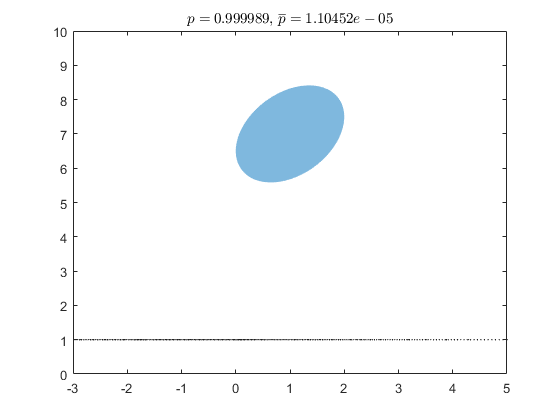

axis([-3 5 0 10])

### Quadratic format

This can only be used if the domain is quadratic.

$y>1$⇒$0.x^2+0.y^2+0.xy+0.x+1.y-1>0$,

i.e. `[0 0; 0 0]*[x;y] + [0;1]*[x;y] -1 > 0`

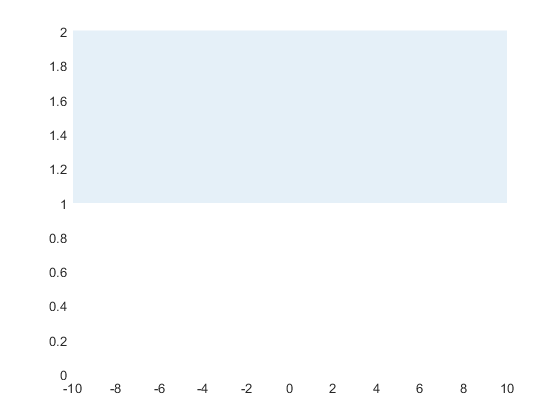

line_quad.q2=zeros(2);
line_quad.q1=[0;1];
line_quad.q0=-1;

plot_boundary(line_quad,2,'dom_type','quad','fill_colors',[0,0.447,0.741])
axis([-10 10 0 2])

[~,pc]=integrate_normal(mu,v,line_quad,'dom_type','quad')

pc =      1.104524849929272e-05


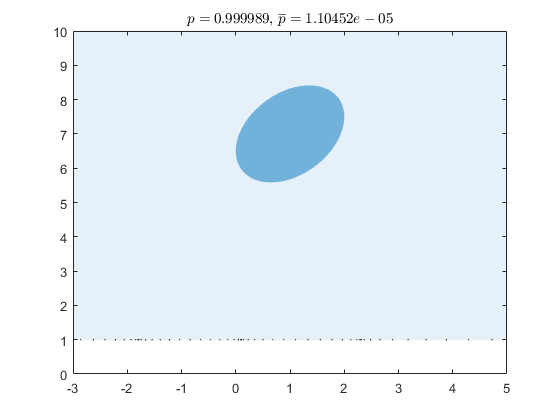

axis([-3 5 0 10])

### Function format

This general function format is simple. But a numerical algorithm is used to find its crossing points in a finite span, so compared to the above two formats, it can be less accurate for the same speed.

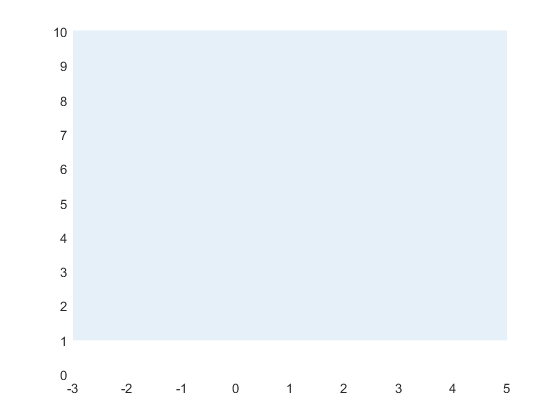

line_fun=@(x,y) y-1;
plot_boundary(line_fun,2,'dom_type','fun','fill_colors',[0,0.447,0.741])

[~,pc]=integrate_normal(mu,v,line_fun,'dom_type','fun')

pc =      1.099030690782967e-05


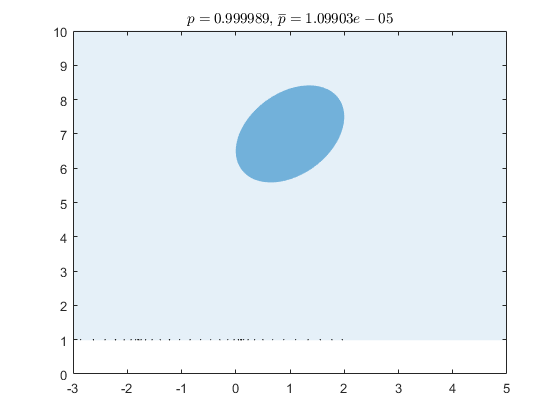

axis([-3 5 0 10])

Improve accuracy by changing `AbsTol`, `RelTol`, `fun_span` or `fun_resol`:

[~,pc]=integrate_normal(mu,v,line_fun,'dom_type','fun','fun_span',10)

pc =      1.104524849929272e-05


axis([-3 5 0 10])

Classify normals and samples using these domain formats.

mu_2=[-1;-2];
v_2=[1 -.5; -.5 2];
n_samp=1e3;
samp_1=mvnrnd(mu,v,n_samp);
samp_2=mvnrnd(mu_2,v_2,n_samp);

### Ray-scan format

results=classify_normals(samp_1,samp_2,'input_type','samp','dom',@line_ray_scan,'dom_type','ray_scan')

results = struct with fields:
    norm_bd_pts: [2×300 double]
    norm_errmat: [2×2 double]
       norm_err: 0.010167875821020
    samp_errmat: [2×2 double]
       samp_err: 0.009000000000000


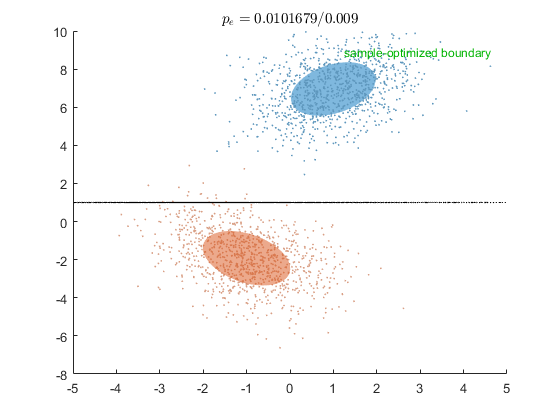

axis([-5 5 -8 10])

### Quadratic format

results=classify_normals(samp_1,samp_2,'input_type','samp','dom',line_quad,'dom_type','quad')

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            -1982         
     1            7            -1985         initial simplex
     2            9            -1986         reflect
     3           10            -1986         reflect
     4           11            -1986         reflect
     5           12            -1986         reflect
     6           13            -1986         reflect
     7           14            -1986         reflect
     8           15            -1986         reflect
     9           16            -1986         reflect
    10           18            -1986         contract outside
    11           26            -1986         shrink
    12           34            -1986         shrink
    13           42            -1986         shrink
    14           50            -1986         shrink
    15           58            -1986         shrink
    16           66            -1986         shrink
    17           74            -1986  

results = struct with fields:
        norm_bd_pts: [2×300 double]
        norm_errmat: [2×2 double]
           norm_err: 0.010167875821020
        samp_errmat: [2×2 double]
           samp_err: 0.009000000000000
            samp_dv: {[1000×1 double]  [1000×1 double]}
        samp_opt_bd: [1×1 struct]
        samp_opt_dv: {[1000×1 double]  [1000×1 double]}
    samp_opt_bd_pts: [2×39619 double]
    samp_opt_errmat: [2×2 double]
       samp_opt_err: 0.007000000000000


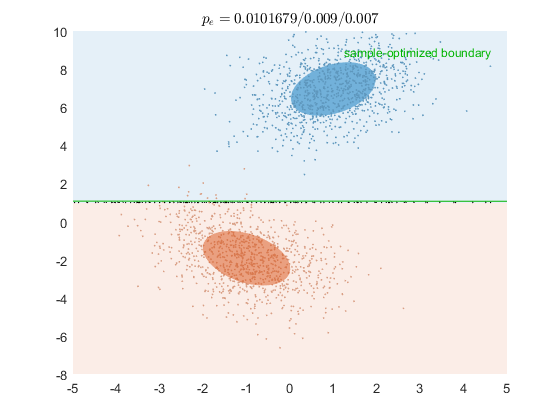

axis([-5 5 -8 10])

### Function format

results=classify_normals(samp_1,samp_2,'input_type','samp','dom',line_fun,'dom_type','fun')

results = struct with fields:
    norm_bd_pts: [2×120 double]
    norm_errmat: [2×2 double]
       norm_err: 0.010167842628905
    samp_errmat: [2×2 double]
       samp_err: 0.009000000000000
        samp_dv: {[1000×1 double]  [1000×1 double]}


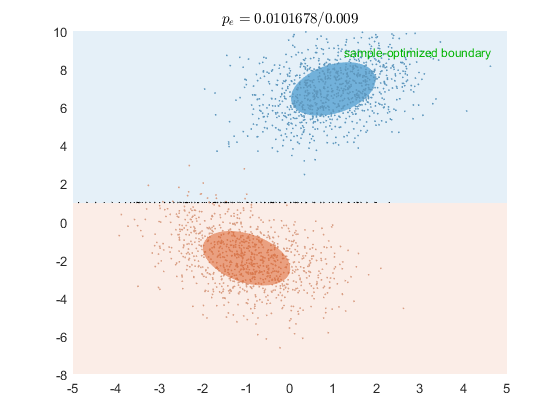

axis([-5 5 -8 10])

## [[paper fig. 2e]](https://arxiv.org/abs/2012.14331) Classify in 2d with non-normal samples

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            -1547         
     1            7            -1553         initial simplex
     2            9            -1563         expand
     3           10            -1563         reflect
     4           11            -1563         reflect
     5           12            -1563         reflect
     6           14            -1579         expand
     7           15            -1579         reflect
     8           16            -1579         reflect
     9           18            -1589         expand
    10           20            -1607         expand
    11           21            -1607         reflect
    12           23            -1635         expand
    13           24            -1635         reflect
    14           25            -1635         reflect
    15           27            -1691         expand
    16           28            -1691         reflect
    17           29            -1691         re

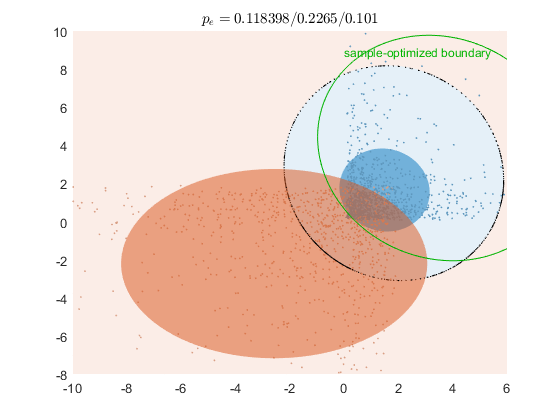

results = struct with fields:
            norm_bd: [1×1 struct]
        norm_bd_pts: [2×492 double]
        norm_errmat: [2×2 double]
           norm_err: 0.118397934999901
      norm_dprime_o: 2.366067005009047
      norm_dprime_a: 1.407263459341172
      norm_dprime_e: 1.562577792283544
        samp_errmat: [2×2 double]
           samp_err: 0.226500000000000
        samp_dprime: 1.500845943200996
            samp_dv: {[1000×1 double]  [1000×1 double]}
        samp_opt_bd: [1×1 struct]
        samp_opt_dv: {[1000×1 double]  [1000×1 double]}
    samp_opt_bd_pts: [2×28646 double]
    samp_opt_errmat: [2×2 double]
       samp_opt_err: 0.101000000000000
    samp_opt_dprime: 2.551748358298260


n_samp=1e3;
samp_1=exp(mvnrnd([0 0],eye(2),n_samp));
samp_2=-exp(mvnrnd([1 1],eye(2),n_samp))+[2 2];

results=classify_normals(samp_1,samp_2,'input_type','samp')

## [[paper fig. 2a, bottom]](https://arxiv.org/abs/2012.14331) Set operations on integration/classification domains

mu=[0;0]; v=[.5 0; 0 1];

left_circle_fun=@(x,y) -(x+1).^2-y.^2+5;
right_circle_fun=@(x,y) -(x-1).^2-y.^2+5;

Union of the two circles is: left circle >0 or right circle equation >0, i.e. max (left circle equation, right circle equation)>0:

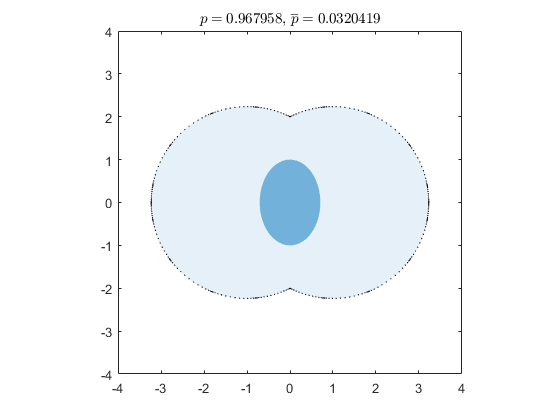

union_fun=@(x,y) max(left_circle_fun(x,y), right_circle_fun(x,y));
integrate_normal(mu,v,union_fun,'dom_type','fun','fun_span',5);
axis image; axis([-4 4 -4 4])

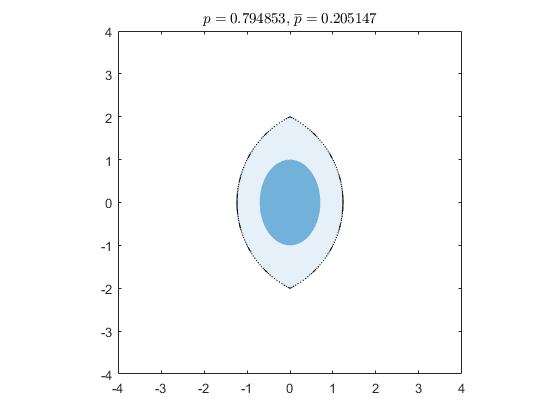

intersection_fun=@(x,y) min(left_circle_fun(x,y), right_circle_fun(x,y));
integrate_normal(mu,v,intersection_fun,'dom_type','fun','fun_span',5);
axis image; axis([-4 4 -4 4])

Create a crescent domain: (left circle) OR  (NOT (right circle)), i.e. left circle equation > 0 or right circle equation < 0, i.e. left circle equation > 0 or minus of right circle equation > 0, i.e. max(left circle equation, minus of right circle equation)>0:

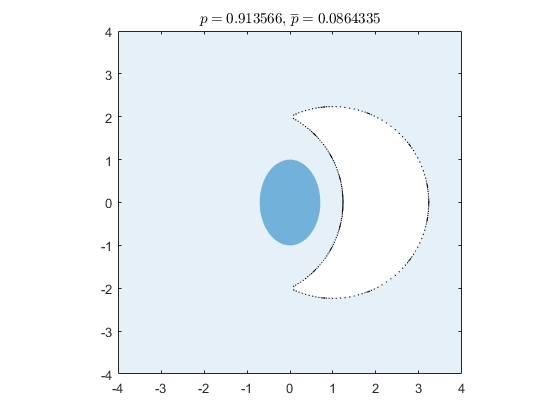

crescent_fun=@(x,y) max(left_circle_fun(x,y), -right_circle_fun(x,y));
integrate_normal(mu,v,crescent_fun,'dom_type','fun','fun_span',5);
axis image; axis([-4 4 -4 4])

Classify normals using this crescent domain:

mu_2=[2.2;0]; v_2=[.5 0; 0 .25];
results=classify_normals([mu,v],[mu_2,v_2],'dom',crescent_fun,'dom_type','fun')

results = struct with fields:
    norm_bd_pts: [2×586 double]
    norm_errmat: [2×2 double]
       norm_err: 0.1235


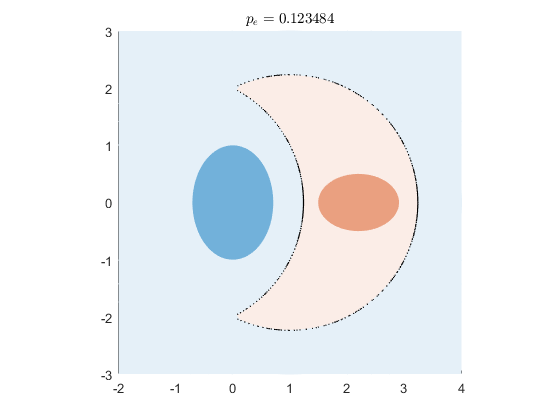

axis image; axis([-2 4 -3 3])

### Ray-scan the domains and use domain operations

Do all of the above by using set operations on faster/more accurate ray-scan domains.

First, define the circles as quadratic domains, then ray-scan them:

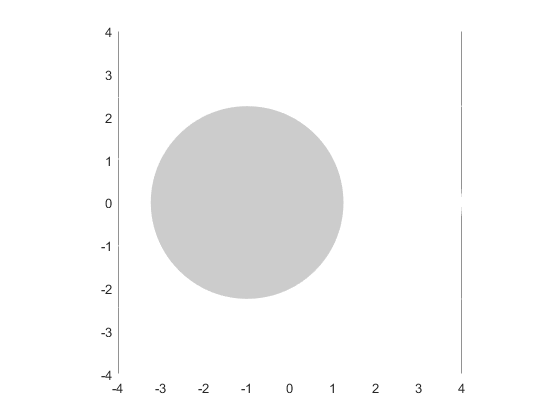

left_circle_quad.q2=-eye(2);
left_circle_quad.q1=[-2;0];
left_circle_quad.q0=4;

plot_boundary(left_circle_quad,2,'fill_colors',[1 1 1; .8*[1 1 1]])
axis image; axis([-4 4 -4 4])

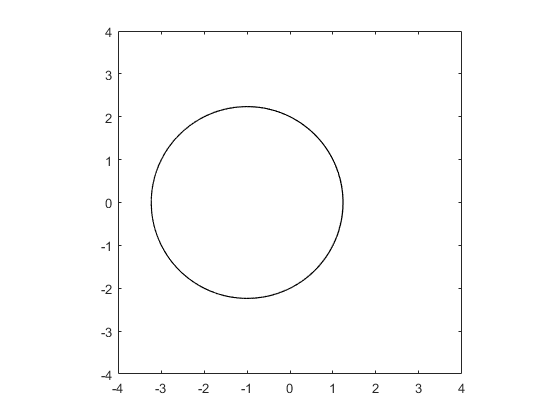

left_circle_ray_scan=@(n,orig) standard_ray_scan(left_circle_quad,n,'mu',orig);
plot_boundary(left_circle_ray_scan,2,'dom_type','ray_scan')
axis image; axis([-4 4 -4 4])


right_circle_quad=left_circle_quad;
right_circle_quad.q1=[2;0];

right_circle_ray_scan=@(n,orig) standard_ray_scan(right_circle_quad,n,'mu',orig);

Now use set operations on the domains:

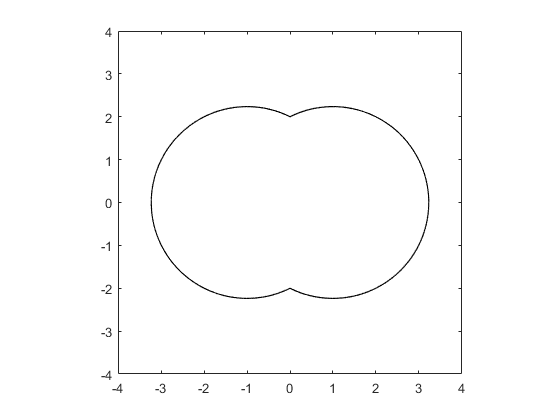

union_ray_scan=@(n,orig) combine_ray_scan_doms({left_circle_ray_scan,right_circle_ray_scan},'or',n,'orig',orig);
plot_boundary(union_ray_scan,2,'dom_type','ray_scan')
axis image; axis([-4 4 -4 4])

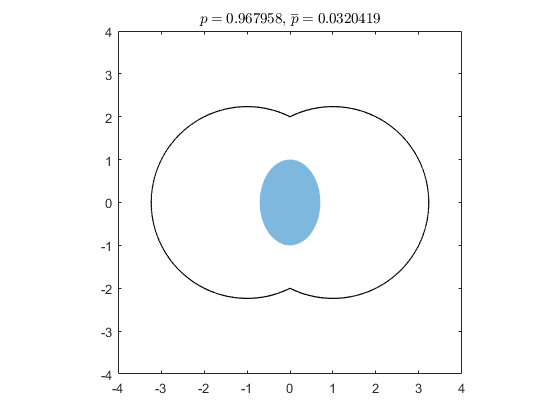

integrate_normal(mu,v,union_ray_scan,'dom_type','ray_scan');
axis image; axis([-4 4 -4 4])

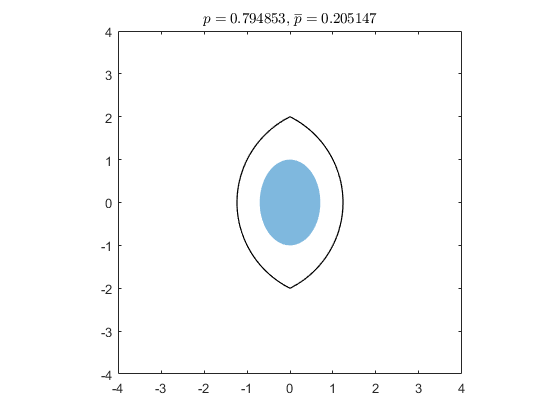

intersection_ray_scan=@(n,orig) combine_ray_scan_doms({left_circle_ray_scan,right_circle_ray_scan},'and',n,'orig',orig);
integrate_normal(mu,v,intersection_ray_scan,'dom_type','ray_scan');
axis image; axis([-4 4 -4 4])

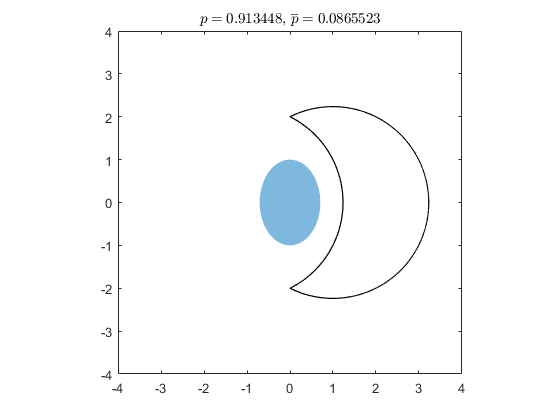

inv_right_circle_ray_scan=@(n,orig) invert_ray_scan_dom(right_circle_ray_scan,n,'orig',orig);
crescent_ray_scan=@(n,orig) combine_ray_scan_doms({left_circle_ray_scan,inv_right_circle_ray_scan},'or',n,'orig',orig);
integrate_normal(mu,v,crescent_ray_scan,'dom_type','ray_scan');
axis image; axis([-4 4 -4 4])

mu_2=[2.2;0]; v_2=[.5 0; 0 .25];
results=classify_normals([mu,v],[mu_2,v_2],'dom',crescent_ray_scan,'dom_type','ray_scan')

results = struct with fields:
    norm_bd_pts: [2×604 double]
    norm_errmat: [2×2 double]
       norm_err: 0.1235


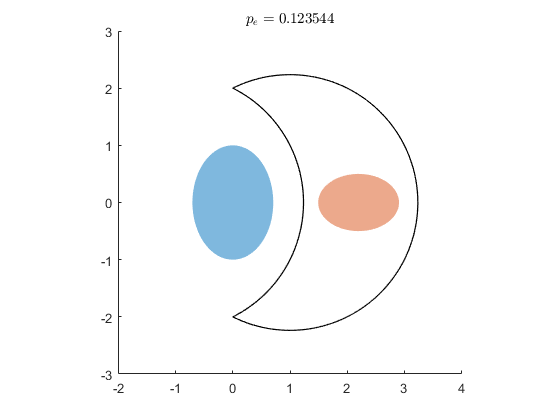

axis image; axis([-2 4 -3 3])

## Classify in 3d

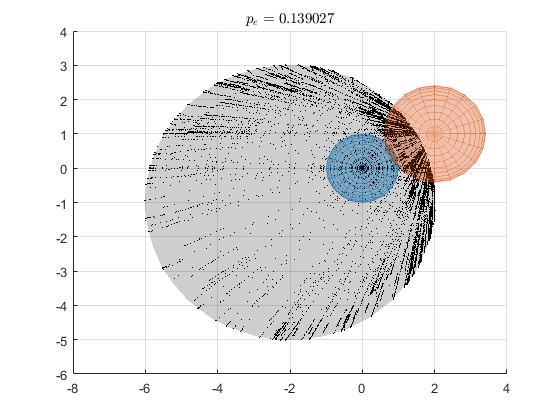

results = struct with fields:
          norm_bd: [1×1 struct]
      norm_bd_pts: [3×11936 double]
      norm_errmat: [2×2 double]
         norm_err: 0.139027033868878
    norm_dprime_o: 2.169402167446128
    norm_dprime_a: 2
    norm_dprime_e: 2.029223744709153


mu_1=[0;0;0]; v_1=eye(3);
mu_2=[2;1;1]; v_2=2*eye(3);

results=classify_normals([mu_1,v_1],[mu_2,v_2])

## Estimate tiny errors (large $d'$) with high accuracy

format long
dprime_true=75

dprime_true =     75


mu_1=[0;0;0]; v=eye(3);
mu_2=dprime_true*[1;0;0];

results=classify_normals([mu_1,v],[mu_2,v],'AbsTol',0,'RelTol',1e-2)

results = struct with fields:
          norm_bd: [1×1 struct]
      norm_bd_pts: [3×14112 double]
      norm_errmat: [2×2 double]
         norm_err: 4.608155172364448e-308
    norm_dprime_o: 74.999967581801229
    norm_dprime_a: 75
    norm_dprime_e: 75


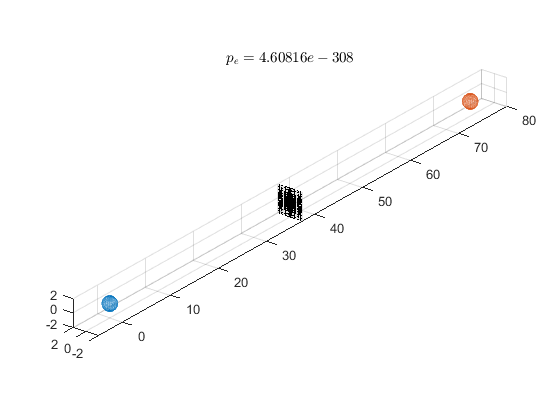

axis image; axis([-5 80 -2 2 -2 2]); view(-53,25)

dprime_computed=results.norm_dprime_o

dprime_computed =   74.999967581801229


format

## [[paper fig. 4a]](https://arxiv.org/abs/2012.14331) accuracy vs separation between the normals

mu_1=[0;0;0];

% both normals have the same covariance, so we can check against
% the true d' (Mahalanobis distance).
v=[1 .5 .7;
  .5  2  1 ;
  .7  1  3];

steps=linspace(1,100,10);
d_true=nan(size(steps));
d_gx2=nan(size(steps));
d_ray=nan(size(steps));

parfor i=1:length(steps)
    i
    mu_2=steps(i)*[1;1;1];
    
    results_gx2=classify_normals([mu_1,v],[mu_2,v],'method','gx2','AbsTol',0,'RelTol',0,'plotmode',false);
    d_true(i)=results_gx2.norm_dprime_a;
    d_gx2(i)=results_gx2.norm_dprime_o;
    
    results_ray=classify_normals([mu_1,v],[mu_2,v],'method','ray','AbsTol',0,'RelTol',0,'plotmode',false);
    d_ray(i)=results_ray.norm_dprime_o;
end


ans =

     1


ans =

     2


ans =

     3


ans =

     4

> In integral2Calc>integral2t/tensor (line 247)
In integral2Calc>integral2t (line 55)
In integral2Calc (line 9)
In integral2 (line 106)
In int_norm_ray (line 45)
In integrate_normal (line 88)
In classify_normals (line 200)
In parallel_function>make_general_channel/channel_general (line 832)
In remoteParallelFunction (line 67)
> In integral2Calc>integral2t/tensor (line 247)
In integral2Calc>integral2t (line 55)
In integral2Calc (line 9)
In integral2 (line 106)
In int_norm_ray (line 44)


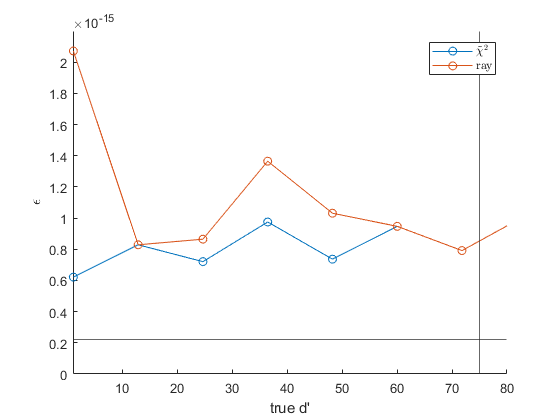


rel_err_gx2=abs(d_gx2-d_true)./d_true;
rel_err_ray=abs(d_ray-d_true)./d_true;

figure; hold on
plot(d_true,rel_err_gx2,'-o')
plot(d_true,rel_err_ray,'-o')
xline(-2*norminv(realmin)) % largest computable d', corr. to the smallest possible error representable in double-precision 
yline(eps) % machine epsilon for double precision
axis([1 80 0 2.2e-15])
xlabel 'true d'''
ylabel('$\epsilon$','interpreter','latex')
legend({'$\tilde{\chi}^2$','ray'},'interpreter','latex')

## [[paper fig. 2a, top]](https://arxiv.org/abs/2012.14331) Integrate normal in a torus defined by function $f(x_1,x_2,x_3)>0$

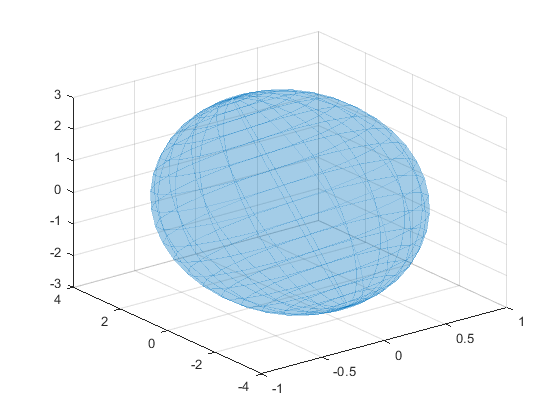

mu=[0;0;0];
v=[1 0 0;
   0 8 4;
   0 4 8];

% plot the error ellipsoid of the normal
plot_normal(mu,v);

fun_torus=@(x1,x2,x3) 1.5-(5-(x1.^2+x2.^2).^0.5).^2-x3.^2;
integrate_normal(mu,v,fun_torus,'dom_type','fun','fun_span',3,'fun_resol',10,'RelTol',1e-1);

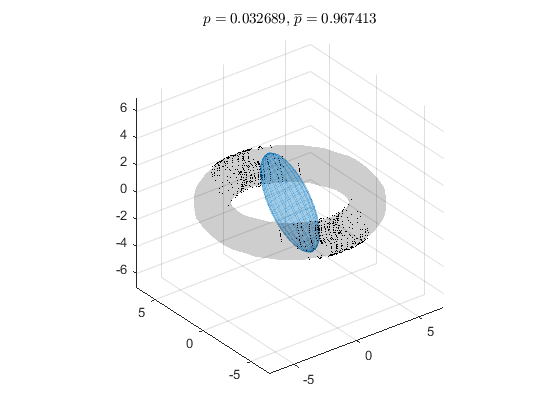

axis image; axis([-7 7 -7 7 -7 7])

### Plot the pdf and cdf of $f(x)$

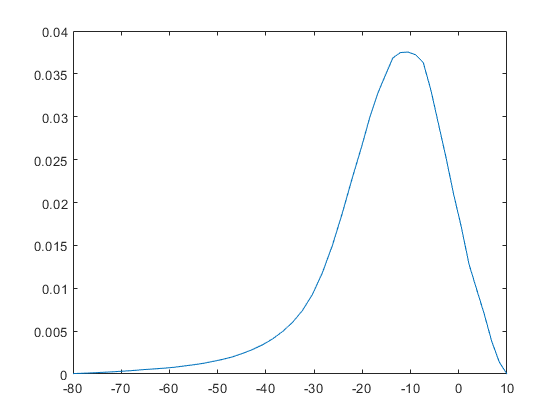

x=[linspace(-80,-20,30) linspace(-20,10,20)];
f=norm_fun_pdf(x,mu,v,fun_torus,'fun_span',3,'fun_resol',10,'RelTol',1e-1,'dx',8);
plot(x,f)

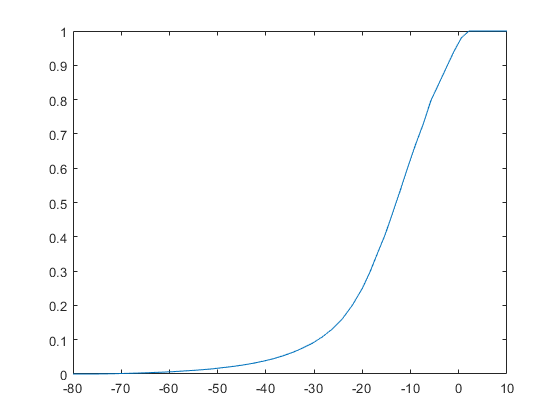

p=norm_fun_cdf(x,mu,v,fun_torus,'fun_span',3,'fun_resol',10,'RelTol',1e-1);
plot(x,p)

## [[paper fig. 2g, top]](https://arxiv.org/abs/2012.14331) Integrate normal in 4d

outside the sphere of radius 5, i.e. $x1^2+x2^2+x3^2+x4^2>5^2$, i.e. `x'*eye(4)*x + zeros(4,1)'*x -25 >0`

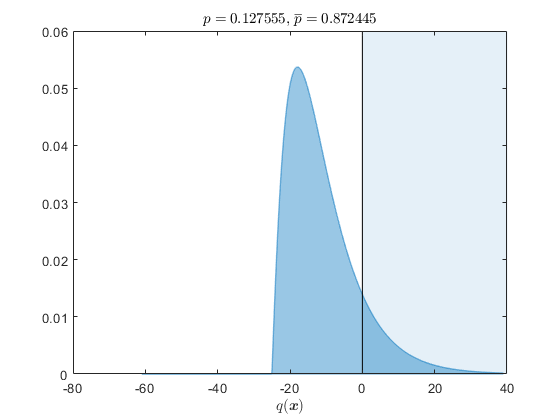

p =    0.127555145337363


mu=[1;1;1;1]; v=diag([1 2 3 4]);

quad.q2=eye(4);
quad.q1=zeros(4,1);
quad.q0=-25;

p=integrate_normal(mu,v,quad)

## [[paper fig. 2g, bottom]](https://arxiv.org/abs/2012.14331) Classify in 4d, with priors and outcome values

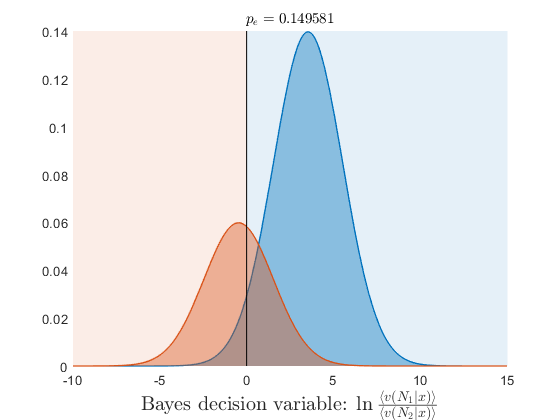

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.149581230491687
    norm_valmat: [2×2 double]
       norm_val: 1.523577241806977


mu_1=[0;0;0;0]; v_1=eye(4);
mu_2=[1;1;1;1]; v_2=eye(4);

% here the Bayes decision variable is normally distributed
results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[2 0; 0 1])

mu_1=[0;0;0;0];
v_1=[1 0 0 0;
     0 2 -1 0;
     0 -1 3 2;
     0 0 2 4];

mu_2=1.5*[1;1;1;1];
v_2=diag([2 2 2 1]);


Correct classification of class 1 is valued 4x than class 2:

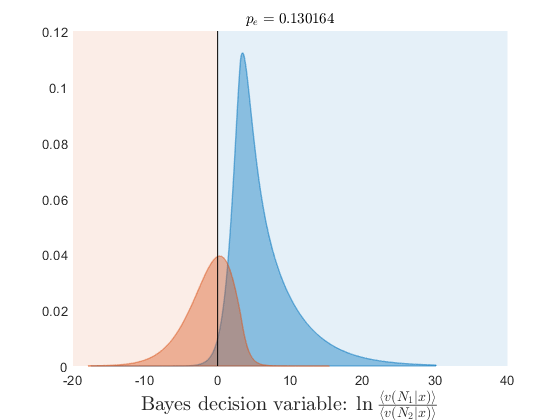

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_errmat: [2×2 double]
       norm_err: 0.130164300239013
    norm_valmat: [2×2 double]
       norm_val: 2.943117525498786


% here the Bayes decision variable is distributed as a generalized chi-square
results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[4 0; 0 1])

Use ray method (with Monte Carlo integration):

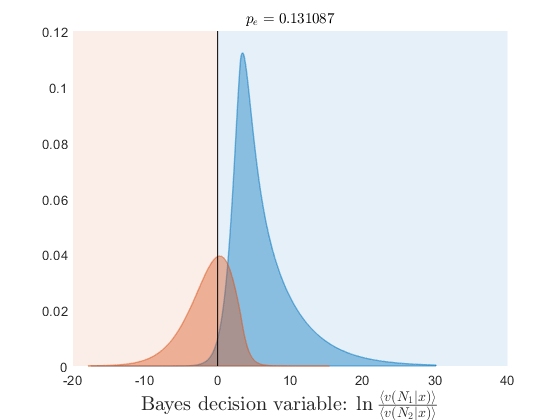

results = struct with fields:
        norm_bd: [1×1 struct]
    norm_bd_pts: [4×2526 double]
    norm_errmat: [2×2 double]
       norm_err: 0.131087488475435
    norm_valmat: [2×2 double]
       norm_val: 2.946569875542951


results=classify_normals([mu_1,v_1],[mu_2,v_2],'prior_1',.7,'vals',[4 0; 0 1],'method','ray','mc_samples',1e3)

Now classify using samples:

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            -4561         
     1           16            -4565         initial simplex
     2           18            -4590         expand
     3           19            -4590         reflect
     4           20            -4590         reflect
     5           21            -4590         reflect
     6           22            -4590         reflect
     7           23            -4590         reflect
     8           24            -4590         reflect
     9           25            -4590         reflect
    10           26            -4590         reflect
    11           27            -4590         reflect
    12           28            -4590         reflect
    13           29            -4590         reflect
    14           30            -4590         reflect
    15           31            -4590         reflect
    16           32            -4590         reflect
    17           33            -4590      

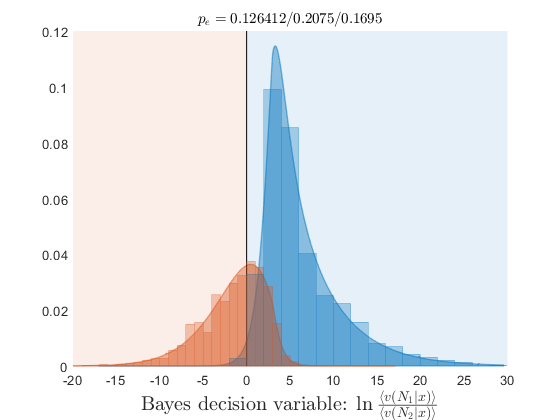

results = struct with fields:
            norm_bd: [1×1 struct]
        norm_errmat: [2×2 double]
           norm_err: 0.126412277736663
        norm_valmat: [2×2 double]
           norm_val: 2.948938955179504
        samp_errmat: [2×2 double]
           samp_err: 0.207500000000000
        samp_valmat: [2×2 double]
           samp_val: 4561
            samp_dv: {[1000×1 double]  [1000×1 double]}
        samp_opt_bd: [1×1 struct]
        samp_opt_dv: {[1000×1 double]  [1000×1 double]}
    samp_opt_errmat: [2×2 double]
       samp_opt_err: 0.169500000000000
    samp_opt_valmat: [2×2 double]
       samp_opt_val: 4598


n_samp=1e3;
results=classify_normals(mvnrnd(mu_1',v_1,n_samp),mvnrnd(mu_2',v_2,n_samp),'input_type','samp','prior_1',.7,'vals',[4 0; 0 1])

## [[paper fig. 2b]](https://arxiv.org/abs/2012.14331) Integrate in a 4d polyhedron, using Monte Carlo

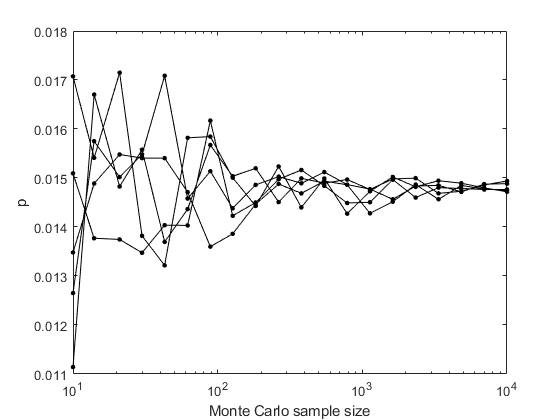

mu=zeros(4,1);
v=eye(4);

fun=@(x1,x2,x3,x4) abs(x1)+abs(x2)+abs(x3)+abs(x4);

% find p(f(x)<1)
mc_samples=round(10.^linspace(1,4,20)); % # of Monte Carlo samples
n_repeat=5;
plist=nan(length(mc_samples),n_repeat);

for k=1:n_repeat
    for i=1:length(mc_samples)
        [~,p]=integrate_normal(mu,v,fun,'dom_type','fun','fun_level',1,'fun_span',3,'fun_resol',10,'mc_samples',mc_samples(i),'plotmode',0);
        plist(i,k)=p;
    end
end

plot(mc_samples,plist,'-k','marker','.','markersize',10)
xlabel 'Monte Carlo sample size'; ylabel 'p'
set(gca,'xscale','log')

Compute cdf and pdf of the polyhedral function

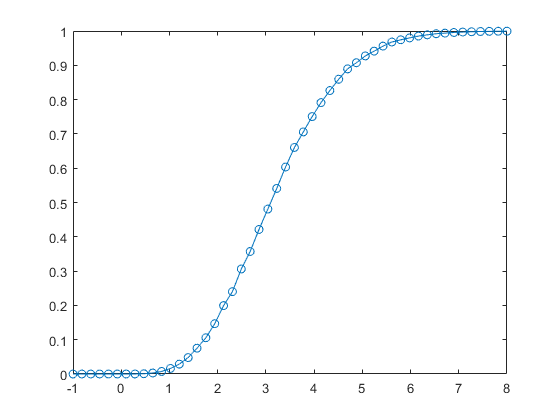

x=linspace(-1,8,50);
p=norm_fun_cdf(x,mu,v,fun);
plot(x,p,'-o')

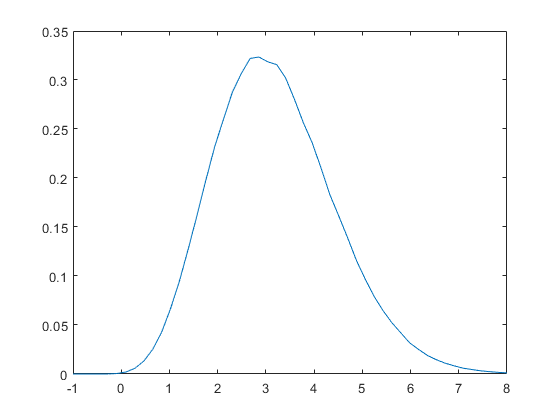

f=norm_fun_pdf(x,mu,v,fun,'dx',0.5,'mc_samples',5e3);
plot(x,f)

## Classifying 3 1d normals

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3


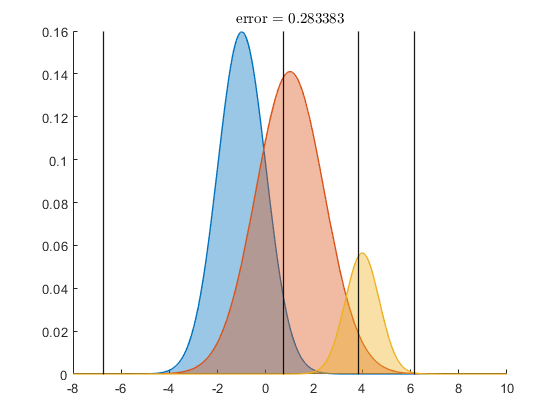

results = struct with fields:
    norm_bd_pts: {3×1 cell}
    norm_errmat: [3×3 double]
       norm_err: 0.2834
    norm_valmat: [3×3 double]
       norm_val: 1.8466


normals=struct;
normals(1).mu=-1; normals(1).v=1;
normals(2).mu=1; normals(2).v=2;
normals(3).mu=4; normals(3).v=.5;

% priors and outcome values
priors=[.4 .5 .1];
vals=[4 0 0; 0 1 -2; 0 0 1];

results=classify_normals_multi(normals,'priors',priors,'vals',vals)

## Classifying 4 2d normals

Define struct of all normals:

normals=struct;
normals(1).mu=[1;0]; normals(1).v=2*eye(2);
normals(2).mu=[0;1]; normals(2).v=eye(2);
normals(3).mu=[-1;0]; normals(3).v=eye(2);
normals(4).mu=[0;-1]; normals(4).v=eye(2);

Plot the multi-class boundary of normal 3:

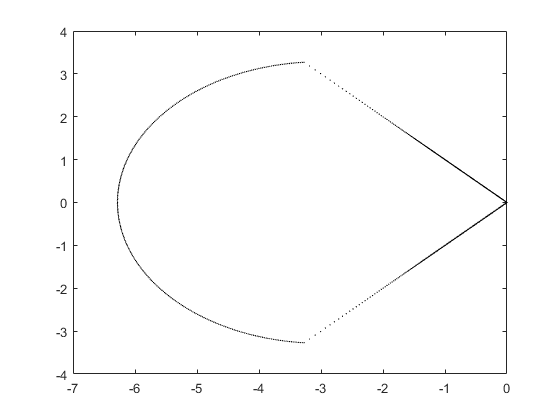

plot_boundary(@(n,orig) opt_class_multi(n,normals,3,'orig',orig),2,'mu',normals(3).mu,'dom_type','ray_scan')

Classify:

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


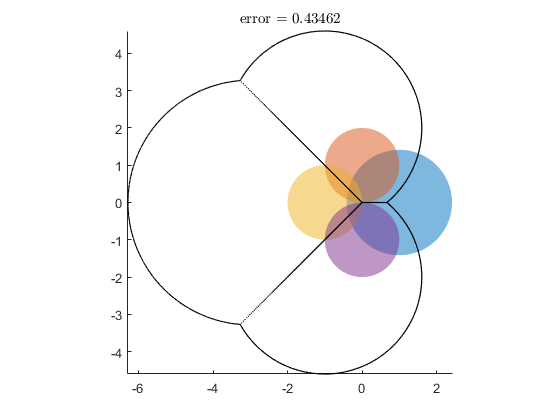

results=classify_normals_multi(normals); axis image

Now classify using samples from these normals, with outcome values:

samples=struct;
for i=1:4
    samples(i).sample=mvnrnd(normals(i).mu,normals(i).v,1e4);
end
vals=diag([1 2 3 4]);
results_samp=classify_normals_multi(samples,'input_type','samp','vals',vals)

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


results_samp = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.4625
    norm_valmat: [4×4 double]
       norm_val: 1.5488
    samp_errmat: [4×4 double]
       samp_err: 0.4614
    samp_valmat: [4×4 double]
       samp_val: 62091


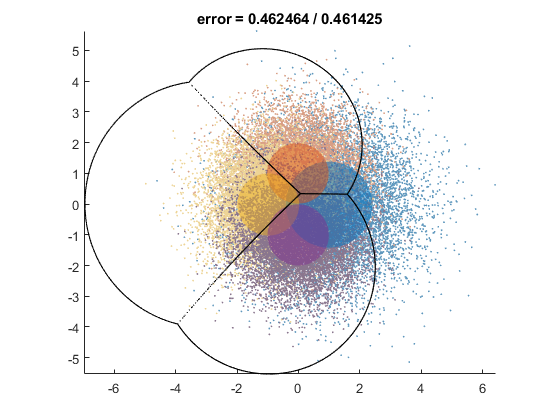

axis image

Now classify using samples from t distributions similar to these normals:

samples=struct;
for i=1:4
    samples(i).sample=mvtrnd(normals(i).v,3,1e4)+normals(i).mu';
end
results_samp=classify_normals_multi(samples,'input_type','samp')

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


results_samp = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.5603
    samp_errmat: [4×4 double]
       samp_err: 0.4537


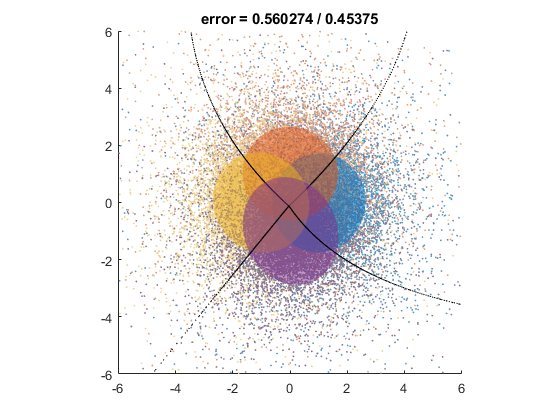

axis image; axis([-6 6 -6 6])

## [[paper fig. 2f]](https://arxiv.org/abs/2012.14331) Classifying 7 2d normals

normals=struct;
normals(1).mu=[2;0]; normals(1).v=[2 1; 1 2];
normals(2).mu=[0;1]; normals(2).v=[.5 0; 0 1];
normals(3).mu=[-1;0]; normals(3).v=[1 .3; .3 1];
normals(4).mu=[0;-1]; normals(4).v=[.5 -.5; -.5 1];
normals(5).mu=[-2;2]; normals(5).v=.5*[1 1; 1 5];
normals(6).mu=[2;-3]; normals(6).v=.3*eye(2);
normals(7).mu=[-2;-2.5]; normals(7).v=[1 0; 0 .1];

results=classify_normals_multi(normals)

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 1 in domain 5
Integrating normal 1 in domain 6
Integrating normal 1 in domain 7
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 2 in domain 5
Integrating normal 2 in domain 6
Integrating normal 2 in domain 7
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 3 in domain 5
Integrating normal 3 in domain 6
Integrating normal 3 in domain 7
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4
Integrating normal 4 in domain 5
Integrating normal 4 in domain 6
Integrating normal 4 in domain 7
Integrating normal 5 in domain 1
Integrating normal 5 in domain 2
Integratin

results = struct with fields:
    norm_bd_pts: {7×1 cell}
    norm_errmat: [7×7 double]
       norm_err: 0.2319


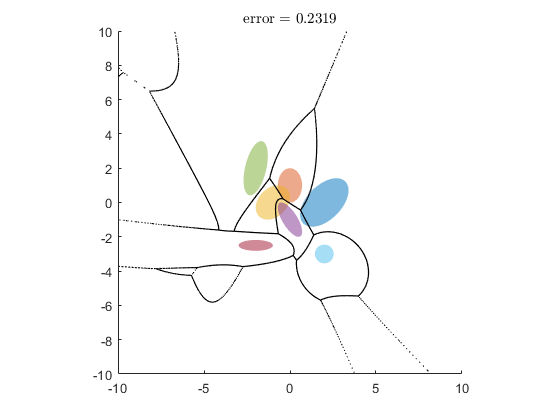

axis image; axis([-10 10 -10 10])

## Classifying 4 3d normals

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


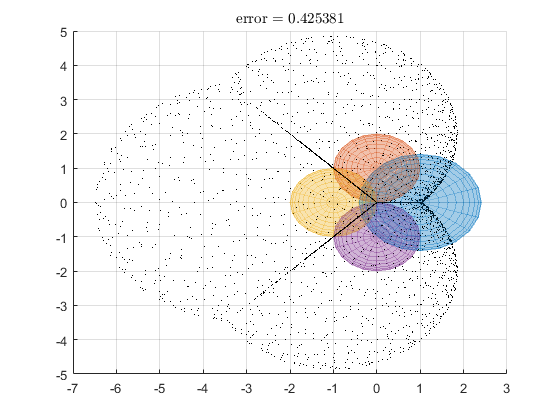

results = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.4254


normals=struct;
normals(1).mu=[1;0;0]; normals(1).v=2*eye(3);
normals(2).mu=[0;1;0]; normals(2).v=eye(3);
normals(3).mu=[-1;0;0]; normals(3).v=eye(3);
normals(4).mu=[0;-1;0]; normals(4).v=eye(3);

results=classify_normals_multi(normals)

## [[paper fig. 2h]](https://arxiv.org/abs/2012.14331) Classifying 4 4d $t$ distribution samples

Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 3
Integrating normal 2 in domain 4
Integrating normal 3 in domain 1
Integrating normal 3 in domain 2
Integrating normal 3 in domain 3
Integrating normal 3 in domain 4
Integrating normal 4 in domain 1
Integrating normal 4 in domain 2
Integrating normal 4 in domain 3
Integrating normal 4 in domain 4


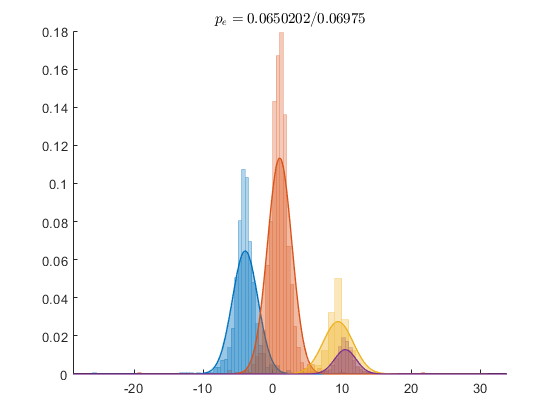

results_samp = struct with fields:
    norm_bd_pts: {4×1 cell}
    norm_errmat: [4×4 double]
       norm_err: 0.0650
    samp_errmat: [4×4 double]
       samp_err: 0.0698


params=struct;
params(1).mu=[0;-4;-2;-2]; params(1).v=diag([1 2 3 4]);
params(2).mu=[1;1;0;0]; params(2).v=eye(4)/4;
params(3).mu=[3;4;5;7]; params(3).v=eye(4);
params(4).mu=[5;5;7;4]; params(4).v=eye(4);

priors=[.3 .5 .15 .05];

n_samp=1e3;
samples=struct;
for i=1:4
    samples(i).sample=mvtrnd(params(i).v,3,n_samp)+params(i).mu';
end
results_samp=classify_normals_multi(samples,'input_type','samp','priors',priors,'mc_samples',1e3,'plotmode',[1;1;1;1])

## [[paper figs. 3a,b](https://arxiv.org/abs/2012.14331)] testing the normal approximation for 2 2d classes

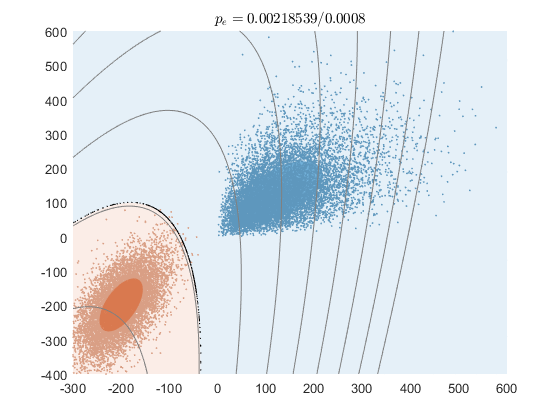

N_samp=1e4; n_samp=1e2;

mu_1=[5 5]; v_1=[1 .5; .5 1]; samp_1=mvnrnd(mu_1,v_1,N_samp).^3; % not normal
mu_2=[-200 -200]; v_2=[1 1; 1 3]*2e3; samp_2=mvnrnd(mu_2,v_2,N_samp);

results=classify_normals(samp_1,samp_2,'input_type','samp','samp_opt',false);
axis([-300 600 -400 600]); hold on
bd=results.norm_bd;

q0s=linspace(-100,35,100)';
true_p11=nan(size(q0s)); true_p2_2=nan(size(q0s)); % p(1|1)
norm_p11=nan(size(q0s)); norm_p2_2=nan(size(q0s));

for i=1:length(q0s)
    bd_shift=bd; bd_shift.q0=q0s(i);
    if ~rem(i,10)
        plot_boundary(bd_shift,2,'plot_type','line','line_color',.5*[1 1 1]);
    end
    results_shift=classify_normals(samp_1,samp_2,'input_type','samp','dom',bd_shift,'samp_opt',false,'plotmode',false);
    
    % true outcomes
    true_p11(i)=results_shift.samp_errmat(1,1)/N_samp;
    true_p2_2(i)=results_shift.samp_errmat(2,2)/N_samp;
    
    % normal outcomes
    norm_p11(i)=results_shift.norm_errmat(1,1)/.5;
    norm_p2_2(i)=results_shift.norm_errmat(2,2)/.5;
    
end

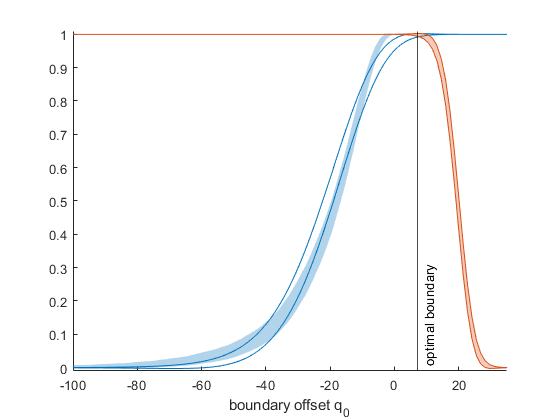

true_p1_1_sd=sqrt(true_p11.*(1-true_p11)/n_samp);
true_p2_2_sd=sqrt(true_p2_2.*(1-true_p2_2)/n_samp);

norm_p1_1_sd=sqrt(norm_p11.*(1-norm_p11)/n_samp);
norm_p2_2_sd=sqrt(norm_p2_2.*(1-norm_p2_2)/n_samp);

figure; hold on
colors=colororder;
xline(bd.q0,'k','optimal boundary','LabelVerticalAlignment','bottom') % optimal criterion

% p(1|1)
x=q0s; y=true_p11; dy=true_p1_1_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],colors(1,:),'facealpha',.3,'linestyle','none');

y=norm_p11; dy=norm_p1_1_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],'k','facecolor','none','edgecolor',colors(1,:));

% p(2|2)
y=true_p2_2; dy=true_p2_2_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],colors(2,:),'facealpha',.3,'linestyle','none');

y=norm_p2_2; dy=norm_p2_2_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],'k','facecolor','none','edgecolor',colors(2,:));

xlim([min(q0s) max(q0s)]); ylim([-.01 1.01]); xlabel('boundary offset q_0')

## [[paper figs. 3c,d]](https://arxiv.org/abs/2012.14331) testing the normal approximation for 4 4d $t$ distributions

n_class=4; N_samp=1e4; n_samp=1e2;

% t distribution parameters
params_t=struct;
params_t(1).mu=[0;-4;-2;-2]; params_t(1).v=diag([1 2 3 4]);
params_t(2).mu=[1;1;0;0]; params_t(2).v=eye(4)/4;
params_t(3).mu=[3;4;5;7]; params_t(3).v=eye(4);
params_t(4).mu=[5;5;7;4]; params_t(4).v=eye(4);

samples=struct; params_samp=struct;
for i=1:4
    % generate t samples
    sample=mvtrnd(params_t(i).v,3,N_samp)+params_t(i).mu';
    samples(i).sample=sample;
    % mean and covariance of samples
    params_samp(i).mu=mean(sample)';
    params_samp(i).v=cov(sample)';
end

len_fam=10;
prior_fam=10.^linspace(-6,12,len_fam)';
vscale_fam=10.^linspace(-1,3,len_fam)';

true_p22_mean=nan(len_fam,1);
true_pe_mean=nan(len_fam,1);
true_pe_sd=nan(len_fam,1);

norm_p22_mean=nan(len_fam,1);
norm_pe_mean=nan(len_fam,1);
norm_pe_sd=nan(len_fam,1);

parfor i=1:len_fam
    i
    % generate family of classification domains
    
    % uncomment when varying prior, comment when varying variance
    priors_shift=[1 prior_fam(i) 1 1]; priors_shift=priors_shift/sum(priors_shift);
    domains_shift=cell(n_class,1);
    for k=1:n_class
        domains_shift{k}=@(n,mu) opt_class_multi(n,params_samp,k,'orig',mu,'priors',priors_shift);
    end
    
    % uncomment when varying variance, comment when varying prior
%     params_samp_shift=params_samp;
%     for k=1:n_class
%         params_samp_shift(k).v=vscale_fam(i)*params_samp(k).v;
%     end    
%     domains_shift=cell(n_class,1);
%     for k=1:n_class
%         domains_shift{k}=@(n,mu,v) opt_class_multi(n,params_samp_shift,k,'mu',mu,'v',v);
%     end
    
    results_shift=classify_normals_multi(samples,'input_type','samp','doms',domains_shift,'mc_samples',5e3,'plotmode',false);
    
    % true error rates
    true_p22_mean(i)=results_shift.samp_errmat(2,2)/N_samp;
    true_pe_mean(i)=results_shift.samp_err;
    samp_errmat_p=results_shift.samp_errmat/(n_class*N_samp);
    errs=sum(~eye(length(samples)).*samp_errmat_p,2);
    accs=diag(samp_errmat_p);
    true_pe_sd(i)=sqrt(sum(errs.*accs)/n_samp);
    
    % normal error rates
    norm_p22_mean(i)=results_shift.norm_errmat(2,2)/sum(results_shift.norm_errmat(2,:));
    norm_pe_mean(i)=results_shift.norm_err;
    errs=sum(~eye(length(samples)).*results_shift.norm_errmat,2);
    accs=diag(results_shift.norm_errmat);
    norm_pe_sd(i)=sqrt(sum(errs.*accs)/n_samp);
    
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).

ans =

     1


ans =

     2


ans =

     3


ans =

     4

Integrating normal 1 in domain 1
Integrating normal 1 in domain 1
Integrating normal 1 in domain 1
Integrating normal 1 in domain 1
Integrating normal 1 in domain 2
Integrating normal 1 in domain 2
Integrating normal 1 in domain 2
Integrating normal 1 in domain 2
Integrating normal 1 in domain 3
Integrating normal 1 in domain 3
Integrating normal 1 in domain 3
Integrating normal 1 in domain 3
Integrating normal 1 in domain 4
Integrating normal 1 in domain 4
Integrating normal 1 in domain 4
Integrating normal 1 in domain 4
Integrating normal 2 in domain 1
Integrating normal 2 in domain 1
Integrating normal 2 in domain 1
Integrating normal 2 in domain 1
Integrating normal 2 in domain 2
Integrating normal 2 in domain 2
Integrating normal 2 in domain 2
Integrating normal 2 in domain 2
Integrating normal 2 in do

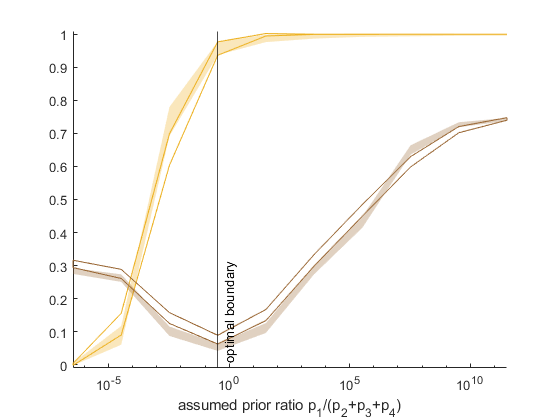

true_p22_sd=sqrt(true_p22_mean.*(1-true_p22_mean)/n_samp);
norm_p22_sd=sqrt(norm_p22_mean.*(1-norm_p22_mean)/n_samp);

figure; hold on;

% uncomment when varying prior, comment when varying variance
xline(1/3,'k','optimal boundary','LabelVerticalAlignment','bottom')
xlabel('assumed prior ratio p_1/(p_2+p_3+p_4)')
x=prior_fam/3;

% uncomment when varying variance, comment when varying prior
% xline(1,'k','optimal boundary','LabelVerticalAlignment','bottom')
% xlabel('assumed variance scale')
% x=vscale_fam;

% p(2|2)
y=true_p22_mean; dy=true_p22_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],[0.9290 0.6940 0.1250],'facealpha',.3,'linestyle','none');

y=norm_p22_mean; dy=norm_p22_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],'k','facecolor','none','edgecolor',[0.9290 0.6940 0.1250]);

% pe
y=true_pe_mean; dy=true_pe_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],[0.6 0.4 0.2],'facealpha',.3,'linestyle','none');

y=norm_pe_mean; dy=norm_pe_sd;
fill([x;flipud(x)],[y-dy;flipud(y+dy)],'k','facecolor','none','edgecolor',[0.6 0.4 0.2]);

xlim([min(x) max(x)]); set(gca,'xscale','log'); ylim([-.01 1.01])

## [[paper fig. 5b]](https://arxiv.org/abs/2012.14331) Actual vision research data: detecting targets on natural scenes

absent=importdata('target_absent.txt',',',1);
present=importdata('target_present.txt',',',1);

results=classify_normals(absent.data,present.data,'input_type','samp')

 
 Iteration   Func-count     min f(x)         Procedure
     0            1            -4569         
     1           11            -4579         initial simplex
     2           13            -4582         expand
     3           14            -4582         reflect
     4           15            -4582         reflect
     5           16            -4582         reflect
     6           17            -4582         reflect
     7           19            -4583         reflect
     8           20            -4583         reflect
     9           21            -4583         reflect
    10           23            -4585         reflect
    11           24            -4585         reflect
    12           25            -4585         reflect
    13           27            -4586         reflect
    14           28            -4586         reflect
    15           29            -4586         reflect
    16           41            -4586         shrink
    17           42            -4586       

results = struct with fields:
            norm_bd: [1×1 struct]
        norm_bd_pts: [3×3754 double]
        norm_errmat: [2×2 double]
           norm_err: 8.0400e-05
      norm_dprime_o: 7.5475
      norm_dprime_a: 6.8175
      norm_dprime_e: 7.3973
        samp_errmat: [2×2 double]
           samp_err: 0.0067
        samp_dprime: 4.9418
            samp_dv: {[2300×1 double]  [2300×1 double]}
        samp_opt_bd: [1×1 struct]
        samp_opt_dv: {[2300×1 double]  [2300×1 double]}
    samp_opt_bd_pts: [3×26070 double]
    samp_opt_errmat: [2×2 double]
       samp_opt_err: 0.0026
    samp_opt_dprime: 5.5866


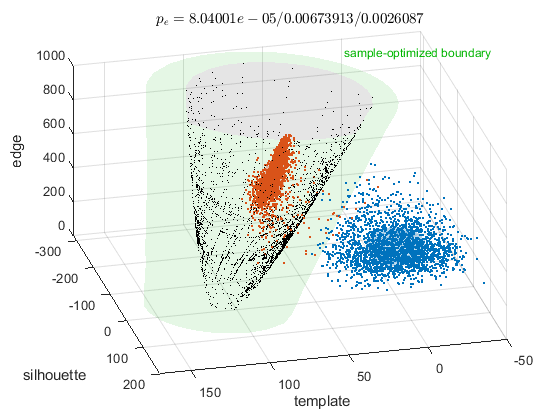

axis([-50 170 -320 200 0 1000]); view(166,40)
xlabel('template'); ylabel('silhouette'); zlabel('edge');

## [[paper figs. 5d-h]](https://arxiv.org/abs/2012.14331) Actual vision research data: detecting camouflage

load camouflage_edge_data
results_joint_2=classify_normals([edge_powers_2(:,1),edge_lpr_2(:,1)],[edge_powers_2(:,2),edge_lpr_2(:,2)],'input_type','samp');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          -199675         
     1            7          -199727         initial simplex
     2            8          -199727         reflect
     3           10          -199727         contract inside
     4           12          -199727         contract inside
     5           14          -199727         contract outside
     6           16          -199727         contract outside
     7           18          -199727         contract inside
     8           20          -199727         contract inside
     9           21          -199727         reflect
    10           23          -199729         contract inside
    11           25          -199754         contract inside
    12           27          -199775         contract inside
    13           29          -199775         contract inside
    14           31          -199775         contract inside
    15           33          -199775         contract ins

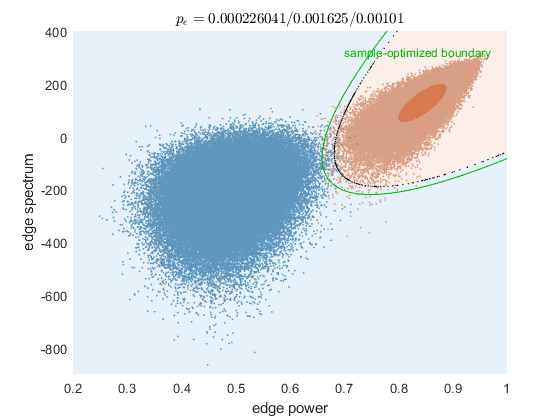

axis([0.2 1 -900 400])
xlabel 'edge power'; ylabel 'edge spectrum'

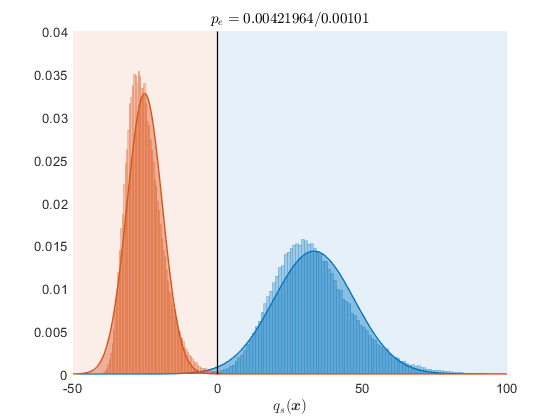

results_dv_2=classify_normals(results_joint_2.samp_opt_dv{1},results_joint_2.samp_opt_dv{2},'input_type','samp','dom',@(x) x,'dom_type','fun','samp_opt',false);
axis([-50 100 0 .04])
xlabel('$q_s(${\boldmath$x$}$)$','interpreter','latex');

results_joint_4=classify_normals([edge_powers_4(:,1),edge_lpr_4(:,1)],[edge_powers_4(:,2),edge_lpr_4(:,2)],'input_type','samp','plotmode',false);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          -195724         
     1            7          -195764         initial simplex
     2            9          -195764         contract inside
     3           11          -195764         contract outside
     4           13          -195764         contract outside
     5           14          -195764         reflect
     6           16          -195764         contract inside
     7           18          -195764         contract inside
     8           20          -195764         contract outside
     9           22          -195764         contract inside
    10           24          -195764         contract inside
    11           26          -195764         contract inside
    12           28          -195764         contract inside
    13           30          -195764         contract inside
    14           32          -195772         contract inside
    15           34          -195790         con

results_joint_8=classify_normals([edge_powers_8(:,1),edge_lpr_8(:,1)],[edge_powers_8(:,2),edge_lpr_8(:,2)],'input_type','samp','plotmode',false);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          -178631         
     1            7          -178631         initial simplex
     2            9          -178631         contract inside
     3           11          -178631         contract inside
     4           13          -178631         contract inside
     5           14          -178631         reflect
     6           16          -178699         contract outside
     7           18          -178838         contract inside
     8           19          -178838         reflect
     9           20          -178838         reflect
    10           22          -178875         contract inside
    11           23          -178875         reflect
    12           25          -178940         contract inside
    13           27          -178980         contract inside
    14           28          -178980         reflect
    15           30          -178980         contract inside
    16           32  

results_dv_joint=classify_normals([results_joint_2.samp_opt_dv{1},results_joint_4.samp_opt_dv{1},results_joint_8.samp_opt_dv{1}],[results_joint_2.samp_opt_dv{2},results_joint_4.samp_opt_dv{2},results_joint_8.samp_opt_dv{2}],'input_type','samp');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          -198731         
     1           11          -198919         initial simplex
     2           12          -198919         reflect
     3           13          -198919         reflect
     4           14          -198919         reflect
     5           15          -198919         reflect
     6           16          -198919         reflect
     7           17          -198919         reflect
     8           19          -199021         expand
     9           20          -199021         reflect
    10           21          -199021         reflect
    11           23          -199165         expand
    12           24          -199165         reflect
    13           25          -199165         reflect
    14           26          -199165         reflect
    15           27          -199165         reflect
    16           29          -199243         expand
    17           30          -199243        

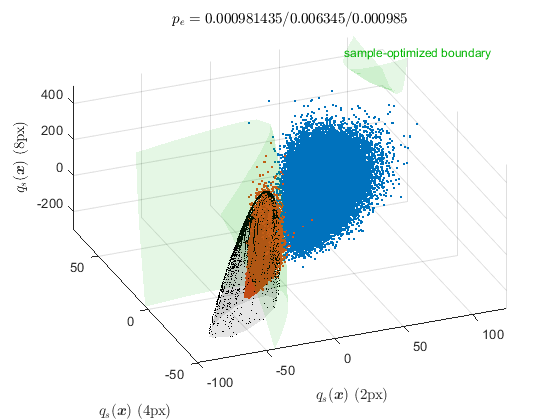

axis([-100 125 -50 75 -300 500]); view(-22,45)
xlabel('$q_s(${\boldmath$x$}$)$ (2px)','interpreter','latex');
ylabel('$q_s(${\boldmath$x$}$)$ (4px)','interpreter','latex');
zlabel('$q_s(${\boldmath$x$}$)$ (8px)','interpreter','latex');

results_all=classify_normals([edge_powers_2(:,1),edge_lpr_2(:,1),...
                              edge_powers_4(:,1),edge_lpr_4(:,1),...
                              edge_powers_8(:,1),edge_lpr_8(:,1)],...
                             [edge_powers_2(:,2),edge_lpr_2(:,2),...
                              edge_powers_4(:,2),edge_lpr_4(:,2),...
                              edge_powers_8(:,2),edge_lpr_8(:,2)],'input_type','samp');

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          -199488         
     1           29          -199691         initial simplex
     2           30          -199691         reflect
     3           31          -199691         reflect
     4           32          -199691         reflect
     5           34          -199691         contract inside
     6           36          -199691         contract inside
     7           38          -199691         contract inside
     8           40          -199691         contract inside
     9           41          -199691         reflect
    10           43          -199691         contract inside
    11           45          -199691         contract inside
    12           46          -199691         reflect
    13           48          -199691         contract inside
    14           50          -199691         contract inside
    15           52          -199691         contract inside
    16           54   

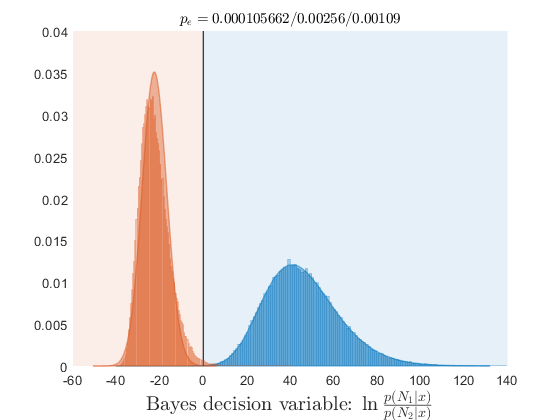

ylim([0 .04])

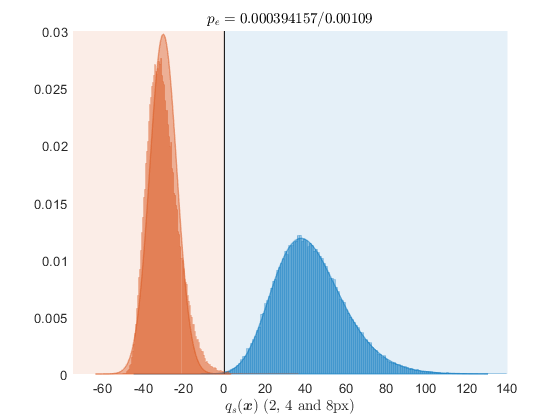

results_all_samp_opt=classify_normals([edge_powers_2(:,1),edge_lpr_2(:,1),...
                              edge_powers_4(:,1),edge_lpr_4(:,1),...
                              edge_powers_8(:,1),edge_lpr_8(:,1)],...
                             [edge_powers_2(:,2),edge_lpr_2(:,2),...
                              edge_powers_4(:,2),edge_lpr_4(:,2),...
                              edge_powers_8(:,2),edge_lpr_8(:,2)],'input_type','samp',...
                              'dom',results_all.samp_opt_bd,'samp_opt',false);
xlabel('$q_s(${\boldmath$x$}$)$ (2, 4 and 8px)','interpreter','latex');
axis([-75 140 0 .03])